%% Demo: Generator derivative-noise robustness (PhDN-G1/G2/G3 / MLP)
% Targeted prior-strength/noise robustness ablation for the PhDN manuscript.
%
% This demo uses the same four-state salient-pole SMIB--linear-AVR system and
% the same G1/G2/G3 prior definitions as the main generator study. Within this
% fixed robustness protocol, state samples and training settings are held fixed
% while only the derivative-noise amplitude is varied. Training and validation
% derivative labels receive per-coordinate relative Gaussian noise, whereas the
% held-out ID-test derivative targets remain clean. OOD data and dynamic
% rollouts are intentionally excluded from this dedicated robustness case.
%
% Protocol:
%   Generator-G1/G2/G3, Ntrain=1000;
%   rho={0, 0.001, 0.005, 0.01};
%   3 rounds;
%   PhDN-G1/G2/G3 and MLP;
%   same state samples and same normalized noise realization across rho within
%   each round; round changes both the noise realization and training seed.

clear; clc;
rng(1);

casemode = 'general';
caseToRun = 'SMIB_AVR';
TrainingSampleList = 1000;       % fixed by the robustness protocol
NoiseLevels = [0,0.001,0.005,0.01];
NValidationSamples = 500;
NIDTestSamples = 1000;
NumRounds = 3;
RoundRandomStateStride = 100;
BaseNoiseSeed = 12001;

% Fixed scrambled-Sobol state samples for the entire ablation.  Unlike the
% sample-efficiency case, these seeds do NOT change with round: only derivative
% noise and optimization randomness change across rounds.
SamplingMethod = 'scrambled_sobol';
SobolScrambleMethod = 'MatousekAffineOwen';
SobolSkip = 1024;
MaxTrainingSamples = TrainingSampleList;
BaseTrainPoolSeed = 7301;
BaseValidationPoolSeed = 7401;
BaseTestPoolSeed = 7501;
BaseOODPoolSeed = 8501;

projectRoot = pwd;
if ~exist(fullfile(projectRoot,'core'),'dir') || ~exist(fullfile(projectRoot,'tasks'),'dir')
    try
        activeFile = matlab.desktop.editor.getActiveFilename;
        projectRoot = fileparts(activeFile);
    catch
        error('Cannot locate the project root. Set the current folder to the framework root.');
    end
end
addpath(genpath(projectRoot));
addpath(fullfile(projectRoot,'system_identification'),'-begin');
addpath(fullfile(projectRoot,'baselines','mlp'),'-begin');
rehash;

OutputCaseRoot = fullfile(projectRoot,'outputs', ...
    'SingleGeneratorDynamic_SMIB_AVR_NoiseRobustness');
OutputSummaryDir = fullfile(OutputCaseRoot,'summary');
if exist(OutputSummaryDir,'dir') ~= 7; mkdir(OutputSummaryDir); end
ResultsFile = fullfile(OutputSummaryDir,'single_generator_dynamic_noise_robustness_results.mat');
CompactRowsFile = fullfile(OutputSummaryDir,'generator_noise_rows.mat'); % lightweight fast-replot row cache

% Optional Stage-0 SR ablation curves. Stage-0 SR has no independent training
% cost, but its saved-result replay/report has independent displayRecordReport_SRx
% controls below. This switch only controls inclusion in robustness tables/figures.
IncludeStage0SRAblationsInComparison = true;

% Plot-only fast path after the expensive sweep has completed.
RegeneratePaperFiguresOnly = false;
PaperFigureVisible = true;
PaperFigureExportPDF = true;
if RegeneratePaperFiguresOnly
    info = regenerate_single_generator_dynamic_noise_robustness_figure( ...
        ResultsFile,OutputSummaryDir,'Visible',PaperFigureVisible, ...
        'ExportPDF',PaperFigureExportPDF, ...
        'IncludeStage0SRAblations',IncludeStage0SRAblationsInComparison);
    fprintf('\nNoise-robustness figure regenerated from:\n%s\n',info.sourceResultsFile);
    return;
end

CaseSimulationWallTimer = tic;
verify_single_generator_dynamic_case_setup( ...
    task_single_generator_dynamic(caseToRun,casemode));

SingleGeneratorDynamic case-local mapping verified: x1=delta, x2=domega, x3=Eqp, x4=Efd
Model variant: salient_pole_flux_decay_linear_avr
Equilibrium max |RHS| = 0.000e+00
Saliency Ksal = -0.47619 | linear AVR gain KA = 10
Rollout IC design verified: hard joint delta-Eqp-Efd OOD with y4/terminal-voltage excitation.



%% Stage 0: fixed SINDy bypass plus native multi-output PySR
% Keep the standard PhDN Stage-0 SINDy-bypass mechanism active in the noise
% ablation.  The bypass criterion is deliberately fixed and noise-level
% agnostic: no injected-noise level or realized noise statistic is supplied to
% Stage 0.  Relative to the earlier 1e-24 setting, the fixed validation-MSE
% tolerance is relaxed to 1e-14 to avoid rejecting numerically exact equations
% solely because of floating-point fitting/reproduction error.
Stage0SingleLayerBypassEnable = true;
Stage0SingleLayerBypassThreshold = 1e-14;

% Fixed SINDy-bypass dictionary only; this is separate from the editable
% native-PySR grammar port defined below.
Stage0BasePolyOrder = 2;
Stage0BaseUnaryOperators = {'inv','sqrt','exp','sin','cos','log'};
Stage0BaseIncludeUnaryOnMonomials = true;
Stage0BaseIncludeOperatorCrossTerms = true;
Stage0BaseIncludeSinCosPair = false;
Stage0BaseMaxLibraryTerms = Inf;
Stage0STLSQThresholdList = [0,1e-8,1e-7,1e-6,1e-5,1e-4,1e-3];
Stage0STLSQMaxIter = 10;
Stage0RidgeLambda = 0;
Stage0WorstOutputWeight = 0.10;

Stage0PythonExe = 'C:\Users\hhy\miniconda3\envs\pysr_sr\python.exe';
Stage0PySRPaperRoot = fullfile(projectRoot,'baselines','pysr_paper_main');
Stage0WorkRoot = fullfile(projectRoot,'tmp','stage0_pysr_single_generator_noise_runs');
Stage0GrammarCasemode = casemode;

% User-editable native-PySR grammar port for this system-identification demo.
% The recommended grammar uses only fine-grained arithmetic, square/square-root,
% and fixed rotor-angle trigonometric atoms.
Stage0UseCustomSRGrammar = true;
% Shared typed physical grammar for all four output dimensions.
% State-dependent division is removed; fixed machine/network denominators are
% absorbed into fitted scalar coefficients.
Stage0SRBinaryOperators = {'+','-','*'};
Stage0SRUnaryOperators = {'square','sqrt','sin','cos'};
Stage0TypedPhysicalPriorEnable = true;
Stage0TypedPhysicalPriorMode = 'single_generator_dynamic';
Stage0SRTrigAllowedVariables = {'x1'};
Stage0SRForbidStateDependentDivision = true;
Stage0SROperatorComplexities = struct();
% SR receives sin(x1) and cos(x1) as fixed derived inputs. Recursive sin/cos
% are removed, so shifted, scaled, polynomial, and nested phases cannot occur.
Stage0SRStrictTrigAtomsOnly = false;
Stage0SRForbidNestedTrig = true;
Stage0SRForbidNestedSquare = true;
Stage0SRForbidNestedSqrt = true;
% PySR 2.0 shared initial-equation library. The robustness case supports
% G1/G2/G3; all three definitions are active prior variants for comparison.
% The outer coefficients shown here are data-regression initializations rather
% than ground-truth parameters.  Official fraction_replaced_guesses periodically
% re-injects the corresponding library into every unresolved output.
% This remains a soft prior: descendants and substructures are not protected.
Stage0SRMinimumPySRVersion = '2.0.0a2';
Stage0SRRequirePySR2 = true;
Stage0SRInitialGuessesEnable = true;
Stage0SRInitialGuessFraction = 0.10;
Stage0SRInitialGuessSingleBases = {};

% G1: coarse Euclidean-magnitude prior.
Stage0SRInitialGuessSparseCombinations_G1 = { ...
    '1.1e-1-1.5e-1*sin(2*x1)',...
    '70-10*x4-43*sqrt(square(x3)+square(x1))'};

% G2: correct trigonometric branch type but no x3--cos(x1) coupling.
Stage0SRInitialGuessSparseCombinations_G2 = { ...
    '5.0e-1-2.0e-2*x3*sin(x1)+6.8e-1*sin(2*x1)',...
    '76-10*x4-49*sqrt(square(x3)+square(sin(x1)))'};

% G3: strongest prior; correct coupled magnitude topology with unit internal
% ratios.  Internal ratios and all final coefficients remain learnable.
Stage0SRInitialGuessSparseCombinations_G3 = { ...
    '5.0e-1-2.0e-2*x3*sin(x1)+6.8e-1*sin(2*x1)',...
    '100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))'};

Stage0SRInitialGuesses_G1 = [Stage0SRInitialGuessSingleBases, ...
    Stage0SRInitialGuessSparseCombinations_G1];
Stage0SRInitialGuesses_G2 = [Stage0SRInitialGuessSingleBases, ...
    Stage0SRInitialGuessSparseCombinations_G2];
Stage0SRInitialGuesses_G3 = [Stage0SRInitialGuessSingleBases, ...
    Stage0SRInitialGuessSparseCombinations_G3];

% Backward-compatible alias and the unique SINDy matched-prior source.
Stage0SRInitialGuesses = Stage0SRInitialGuesses_G3;
% Example broader fallback grammar:
% Stage0SRUnaryOperators = {'square','cube','inv','sqrt','exp','sin','cos','log'};
% Stage0SROperatorComplexities.cube = 3;
% Stage0SROperatorComplexities.exp = 5;
% Stage0SROperatorComplexities.log = 5;

Stage0PopulationSize = 100;
Stage0InnerNumRestarts = 3;
Stage0InnerNIterations = 700;
Stage0InnerPopulations = 36;
Stage0PopulationBudgetMode = 'fixed_total';
Stage0InnerRandomStateStride = 100;

% General output-self-referenced Stage-0 targeted rescue.
% Trigger A: best normalized validation MSE remains above the soft threshold
% AND the ordinary restarts are unstable for that same output.
% Trigger B: the ordinary restarts are relatively consistent, but even their
% best normalized validation MSE remains above the hard threshold.
% A/B both add one official single-output PySR restart. A second rescue restart
% is allowed only if the first reduces the running best q by at least 50% and
% the soft threshold is still not reached. Known derivative-label noise raises
% the soft/hard thresholds above 4x the expected validation-noise MSE floor.
Stage0AdaptiveRescueEnable = true;
Stage0AdaptiveRescueSoftNormalizedMSE = 1e-6;
Stage0AdaptiveRescueHardNormalizedMSE = 1e-3;
Stage0AdaptiveRescueInstabilityFactor = 5;
Stage0AdaptiveRescueContinueImprovementRatio = 0.5;
Stage0AdaptiveRescueUseKnownNoiseFloor = true;
Stage0AdaptiveRescueNoiseFloorMultiplier = 4;
Stage0AdaptiveRescueMaxRestartsPerOutput = 2;
Stage0AdaptiveRescuePopulationMultiplier = 1.5;
Stage0AdaptiveRescueMinPopulations = 8;
Stage0AdaptiveRescueMaxPopulations = 20;
Stage0AdaptiveRescueExplicitPopulations = []; % [] -> adaptive population rule
Stage0AdaptiveRescueNIterations = Stage0InnerNIterations;
Stage0AdaptiveRescueMaxOutputs = 3;
Stage0AdaptiveRescueUseOutputSpecificInitialGuess = true;
Stage0AdaptiveRescueSeedOffset = 10000;
Stage0AdaptiveRescueOutputSeedStride = 1000;
Stage0AdaptiveRescueRestartSeedStride = 100;

% Official PySR growth-biased evolution profile. No candidate receives a custom
% loss or lineage bonus. Instead, user guesses and random individuals remain
% under the same data-loss competition while mutations favor structure-preserving
% outward growth. add_node appends/prepends around the complete tree; insert_node
% wraps a selected existing subtree without changing that subtree internally.
% Direct operator/feature replacement, tree rotation, randomization, deletion,
% and simplification are suppressed. Constants may still mutate or be optimized.
Stage0TournamentSelectionN = 8;
Stage0TournamentSelectionP = 0.85;

% use default settings
Stage0CrossoverProbability = [];

Stage0WeightAddNode        = [];
Stage0WeightInsertNode     = [];
Stage0WeightDeleteNode     = [];
Stage0WeightDoNothing      = [];
Stage0WeightMutateConstant = [];
Stage0WeightMutateOperator = [];
Stage0WeightMutateFeature  = [];
Stage0WeightSwapOperands   = [];
Stage0WeightRotateTree     = [];
Stage0WeightRandomize      = [];
Stage0WeightSimplify       = [];
Stage0WeightOptimize       = [];

Stage0OptimizeProbability = [];
Stage0ShouldSimplify      = [];
% ncycles_per_iteration remains unspecified. Population size, restart count,
% iteration budget, batching, grammar, guesses, and Stage-1/2 remain unchanged.
% Official crossover cannot be restricted to the root, so it is retained only
% at a low probability for occasional combination of independently grown trees.
Stage0MaxDepth = 10;
Stage0MaxSize = 30;
Stage0Parsimony = 1e-6;
Stage0ModelSelection = 'best';
Stage0RandomState = 1;
Stage0Deterministic = false;
Stage0Parallelism = 'multithreading';
% The robustness protocol fixes Ntrain=1000 and does not use PySR batching.
Stage0Batching = false;
Stage0BatchSizeList = TrainingSampleList;
assert(numel(Stage0BatchSizeList)==numel(TrainingSampleList), ...
    'Stage0BatchSizeList must match TrainingSampleList.');
assert(all(Stage0BatchSizeList>=1 & Stage0BatchSizeList<=TrainingSampleList), ...
    ['Every Stage-0 batch size must be a positive integer no larger than ', ...
     'its corresponding training-sample count.']);
Stage0StrictDeterministicTestMode = false;
Stage0RepeatabilityPredictionTolerance = 1e-12;
% All-output, scale-aware machine-precision training early stop.  PySR advances
% in warm-start chunks and stops a restart only after every unresolved output
% reaches the full-training Hall-of-Fame MSE threshold. Remaining restarts are
% skipped only after the fixed external validation set confirms the same floor.
Stage0MachinePrecisionEarlyStopEnable = true;
Stage0MachinePrecisionEarlyStopAbsMSE = 1e-12;
Stage0MachinePrecisionEarlyStopRelMSE = 1e-12;
Stage0MachinePrecisionEarlyStopCheckInterval = 50;
Stage0MachinePrecisionEarlyStopMinIterations = 50;
Stage0MachinePrecisionEarlyStopAcrossRestarts = true;
Stage0Verbosity = 1;
Stage0Progress = false;
Stage0TopKExpressionsToReport = 10;
Stage0DisplayCandidateRankings = true;
Stage0CandidateRankingTopK = 10;
Stage0SemanticDedupTolerance = 1e-8;
Stage0StructureScoreEnable = true;
Stage0StructureValidationMultiplier = 4.0;
Stage0StructureValidationWeight = 0.30;
% Below this scale-aware validation-MSE floor, numerical differences are
% treated as ties and the simpler structure is selected.
Stage0StructureMachineErrorAbsMSEFloor = 1e-12;
Stage0StructureMachineErrorRelMSEFloor = 1e-12;
Stage0StructureFrontierMaxAbs = 20;
Stage0StructureNeighborhoodMaxDistance = 0.55;
Stage0StructureNeighborhoodMinDistance = 0.10;
Stage0StructureNeighborhoodComplexityWindow = 8;

%% Stage 1 and Stage 2
Stage1EnableAugmentation = true;
Stage1AugmentationPolyOrder = Stage0BasePolyOrder;
Stage1AugmentationIncludeCrossTerms = true;
Stage1ForceStage0SeedOnly = true;
Stage1ExpandBoundsToIncludeStage0Seed = true;
Stage1Stage0SeedBoundMargin = 1e-6;
Stage1RequireExactStage0Reproduction = true;
Stage1Stage0ReproductionRelTolerance = 1e-6;
Stage1Stage0ReproductionAbsTolerance = 1e-10;

Stage2Enable = true;
FinalLSQMaxIter = 500;
FinalLSQMaxFunEvals = 5e4;
FinalLSQMaxRelValIncrease = 1e-10;
PostBPPruneEnable = true;
PostBPPruneNumIterations = 1;
PostBPPruneAbsThreshold = 1e-4;
PostBPPruneRelThreshold = 0;
PostBPPruneMaxRelValIncrease = 1e-4;

%% Methods and output controls
InitializationMode = 'skip';
EnableOOD = false;               % clean held-out ID-test vector field only
DisplayDictionary = true;
PrintFinalXiMatrices = false;
FinalXiPrintPrecision = 4;
FinalXiPrintOnlyActive = false;
SaveResults = false;             % legacy sample-efficiency persistence disabled
SaveNoiseResults = false;          % dedicated rho-aware checkpoints
ResultsFile = fullfile(OutputSummaryDir,'single_generator_dynamic_noise_robustness_results.mat');

% -------------------------------------------------------------------------
% Method switches: true always means train the method in the current N/round.
% FINAL low-noise rerun: retrain PhDN-G1/G2/G3 and MLP on
% rho={0,0.001,0.005,0.01}; Stage-0 SR is collected from each PhDN at no
% independent training cost. PhDN-G1/G2/G3 are three independent methods.
% Enabling all three approximately triples the PySR Stage-0 cost relative to
% one PhDN run.
% -------------------------------------------------------------------------
RunPhDNMainModel_G1 = false;
RunPhDNMainModel_G2 = false;
RunPhDNMainModel_G3 = false;
RunMLPBaseline = false;
RunEQLBaseline = false;
RunKANBaseline = false;
RunSINDyBaseline = false;
% Stage-0 SR is a zero-extra-training-cost ablation collected from each PhDN
% Stage 0. Its replay/report display is controlled independently below, while
% IncludeStage0SRAblationsInComparison controls whether SR enters tables/figures.

% -------------------------------------------------------------------------
% Recorded-method replay controls.
% Run*=true always trains and takes priority. Only when Run*=false and the
% corresponding displayRecordReport_*=true is the saved method for the current
% N/round loaded, replayed, and included in robustness tables/figures.
% -------------------------------------------------------------------------
RecordedBaselineSourceRoot = OutputCaseRoot;
RecordedBaselineReplayStrict = false; % backup replay: allow archived configuration mismatch
% Minimal recorded-report mode for replay-only MLX runs. When true, every
% method prints only final architecture/complexity, key ID metrics, and
% timing needed for scientific comparison. Historical sweep/candidate/term
% tables are omitted; saved result structures remain unchanged.
RecordedReportCompactMode = true;
displayRecordReport_PhDN_G1 = true;
displayRecordReport_PhDN_G2 = true;
displayRecordReport_PhDN_G3 = true;
% Stage-0 SR recorded-report controls. These are independent of the PhDN
% replay switches: if true, the saved SR result for the current round/rho is
% loaded/replayed even when the corresponding PhDN report is not replayed.
% They control report replay only; IncludeStage0SRAblationsInComparison
% separately controls inclusion in robustness tables/figures.
displayRecordReport_SR1 = true;
displayRecordReport_SR2 = true;
displayRecordReport_SR3 = true;
displayRecordReport_MLP = true;
displayRecordReport_EQL = false;
displayRecordReport_KAN = false;
displayRecordReport_SINDy = false;

% -------------------------------------------------------------------------
% MLP case-local sweep controls
% Feynman-style depth/activation sweep, with 64 neurons in every hidden layer.
% Depth is the number of affine layers, so depth D has D-1 hidden layers.
% -------------------------------------------------------------------------
MLPSeed = 1;                       % shared round seed for MLP/KAN/EQL
MLPProtocol = 'kan_feynman_sweep';
MLPWidth = 64;
MLPDepthList = 2:6;
MLPActivationList = {'tanh','relu','silu'};
MLPOptimizer = 'LBFGS';
MLPSteps = 500;
MLPLearningRate = 1.0;
MLPDtype = 'float64';
MLPDevice = 'cpu';
MLPTorchNumThreads = 0;
MLPNormalizeInputs = true;
MLPNormalizeOutputs = true;
MLPPythonExe = Stage0PythonExe;
MLPPyKANRoot = fullfile(projectRoot,'third_party','pykan');
MLPWorkRoot = fullfile(projectRoot,'tmp','mlp_single_generator_noise_runs');
MLPDepthEarlyStop = true;
MLPDepthEarlyStopPatience = 1;
MLPDepthEarlyStopRelativeTolerance = 0.0;
MLPDisplaySweepTable = true;
MLPVerbose = true;

% -------------------------------------------------------------------------
% KAN case-local sweep controls
% -------------------------------------------------------------------------
KANPythonExe = Stage0PythonExe;
PyKANRoot = fullfile(projectRoot,'third_party','pykan');
KANWidth = 8;
KANDepthList = 2:6;
KANGridList = [3,5,10,20,50,100,200];
KANSplineOrder = 3;
% Accuracy-first training uses lambda=0 before any sparsification. These mild
% lambdas are attempted only after an accurate unpruned grid checkpoint exists.
KANSparsificationLambdaList = [1e-5,1e-4,1e-3];
KANStepsPerGrid = 200;
KANAccuracyStepsPerGrid = 200;
KANSparsificationSteps = 200;
KANRecoveryStepsPerGrid = 200;
KANOptimizer = 'LBFGS';
KANLearningRate = 1.0;
KANPruneNodeThreshold = 1e-2;
KANPruneEdgeThreshold = 3e-2;
% Both pruned and unpruned fallback branches complete zero-lambda recovery and
% the remaining grid-refinement schedule before validation comparison.
KANPruneValidationGuardEnable = true;
KANPruneMaxRelativeValidationIncrease = 0.0;
KANGridEarlyStop = true;
KANGridEarlyStopPatience = 2;
KANGridEarlyStopRelativeTolerance = 0.015;
KANDepthEarlyStop = true;
KANDepthEarlyStopPatience = 1; % stop after the next meaningfully worse depth
KANDepthEarlyStopRelativeTolerance = 0.01;
% For nested sample sizes, KAN complexity is defined by spline grid G only.
% A larger sample size starts at least from the previously selected G and also
% receives the previous selected native model as a non-regression/warm candidate.
KANEnforceNondecreasingGridAcrossSamples = true;
KANWarmStartAcrossSamples = true;
KANDtype = 'float64';
KANDevice = 'cpu';
KANTorchNumThreads = 0;
KANNormalizeInputs = true;
KANNormalizeOutputs = true;
KANWorkRoot = fullfile(projectRoot,'tmp','kan_single_generator_runs');
KANDisplaySweepTable = true;
KANVerbose = true;

% -------------------------------------------------------------------------
% EQL-Div case-local sweep controls
% -------------------------------------------------------------------------
EQLPythonExe = 'C:\Users\hhy\miniconda3\envs\eql_official\python.exe';
EQLOfficialRoot = fullfile(projectRoot,'baselines','eql','official_eql');
EQLDepthList = [2,3,4,5];
EQLLambdaList = [1e-5,1e-3];
EQLUnitsPerUnaryType = 10;
EQLMultiplicationUnits = 10;
EQLStepsPerHiddenLayer = 3000;
EQLBatchSize = 20;
EQLLearningRate = 1e-3;
EQLGradient = 'adam';
EQLLambdaL2 = 0;
EQLPenaltyEvery = 50;
EQLValidateEvery = 10;
EQLCandidateWorkers = 0;
EQLOfficialVerbose = false;
EQLNormalizeInputs = true;
EQLNormalizeOutputs = true;
EQLTheanoFlags = 'device=cpu,floatX=float64,optimizer=fast_run,exception_verbosity=high';
EQLWorkRoot = fullfile(projectRoot,'tmp','eql_single_generator_runs');
EQLDepthEarlyStop = true;
EQLDepthEarlyStopPatience = 1;
EQLDepthEarlyStopRelativeTolerance = 0.015;
% Paper protocol: every reported point is a model trained on exactly the
% current N samples. The previous smaller-N model is used only as a fixed-Val
% target and optional initialization for a new current-N official EQL run; it
% is never copied unchanged into the current-N paper curve.
EQLFullDepthScheduleEachSample = true;
EQLCheckpointSelectionMode = 'physical_validation_mse';
EQLUsePreviousModelAsSearchTargetAcrossSamples = true;
EQLWarmStartPreviousModel = true;
EQLWarmStartRestarts = 1;
% If the first current-N sweep does not strictly beat the previous fixed-Val
% reference, rerun the best two L/lambda configurations with up to three new
% independent seeds. Early stopping is overridden while the target is pending.
EQLAdaptiveRescueRestarts = 3;
EQLAdaptiveRescueTopK = 2;
EQLStrictImprovementRelativeMargin = 1e-3; % require at least 0.1% fixed-Val improvement
EQLStrictImprovementAbsoluteMargin = 0.0;
EQLStrictTargetOverridesDepthEarlyStop = true;
EQLDisplaySweepTable = true;
EQLVerbose = true;

% Build the complete option structs using the case-local helper, then apply
% every user-facing control above explicitly. The helper is not the hidden
% source of these settings; it only supplies unchanged shared/default fields.
baselineSweep = single_generator_dynamic_baseline_sweep_options( ...
    projectRoot,Stage0PythonExe);
baselineSweep.runMLP = RunMLPBaseline;
baselineSweep.runEQL = RunEQLBaseline;
baselineSweep.runKAN = RunKANBaseline;
baselineSweep.runSINDy = RunSINDyBaseline;

baselineSweep.mlp.protocol = MLPProtocol;
baselineSweep.mlp.width = MLPWidth;
baselineSweep.mlp.depthList = MLPDepthList;
baselineSweep.mlp.activationList = MLPActivationList;
baselineSweep.mlp.optimizer = MLPOptimizer;
baselineSweep.mlp.steps = MLPSteps;
baselineSweep.mlp.learningRate = MLPLearningRate;
baselineSweep.mlp.dtype = MLPDtype;
baselineSweep.mlp.device = MLPDevice;
baselineSweep.mlp.torchNumThreads = MLPTorchNumThreads;
baselineSweep.mlp.normalizeInputs = MLPNormalizeInputs;
baselineSweep.mlp.normalizeOutputs = MLPNormalizeOutputs;
baselineSweep.mlp.pythonExe = MLPPythonExe;
baselineSweep.mlp.pykanRoot = MLPPyKANRoot;
baselineSweep.mlp.workRoot = MLPWorkRoot;
baselineSweep.mlp.depthEarlyStop = MLPDepthEarlyStop;
baselineSweep.mlp.depthEarlyStopPatience = MLPDepthEarlyStopPatience;
baselineSweep.mlp.depthEarlyStopRelativeTolerance = MLPDepthEarlyStopRelativeTolerance;
baselineSweep.mlp.displaySweepTable = MLPDisplaySweepTable;
baselineSweep.mlp.verbose = MLPVerbose;

baselineSweep.kan.pythonExe = KANPythonExe;
baselineSweep.kan.pykanRoot = PyKANRoot;
baselineSweep.kan.width = KANWidth;
baselineSweep.kan.depthList = KANDepthList;
baselineSweep.kan.minimumDepth = min(KANDepthList);
baselineSweep.kan.gridList = KANGridList;
baselineSweep.kan.splineOrder = KANSplineOrder;
baselineSweep.kan.sparsificationLambdaList = KANSparsificationLambdaList;
baselineSweep.kan.stepsPerGrid = KANStepsPerGrid;
baselineSweep.kan.accuracyStepsPerGrid = KANAccuracyStepsPerGrid;
baselineSweep.kan.sparsificationSteps = KANSparsificationSteps;
baselineSweep.kan.recoveryStepsPerGrid = KANRecoveryStepsPerGrid;
baselineSweep.kan.optimizer = KANOptimizer;
baselineSweep.kan.learningRate = KANLearningRate;
baselineSweep.kan.pruneNodeThreshold = KANPruneNodeThreshold;
baselineSweep.kan.pruneEdgeThreshold = KANPruneEdgeThreshold;
baselineSweep.kan.pruneValidationGuardEnable = KANPruneValidationGuardEnable;
baselineSweep.kan.pruneMaxRelativeValidationIncrease = KANPruneMaxRelativeValidationIncrease;
baselineSweep.kan.minimumGrid = min(KANGridList);
baselineSweep.kan.warmStartEnable = KANWarmStartAcrossSamples;
baselineSweep.kan.warmStartCheckpointPath = '';
baselineSweep.kan.warmStartNormalization = struct();
baselineSweep.kan.gridEarlyStop = KANGridEarlyStop;
baselineSweep.kan.gridEarlyStopPatience = KANGridEarlyStopPatience;
baselineSweep.kan.gridEarlyStopRelativeTolerance = KANGridEarlyStopRelativeTolerance;
baselineSweep.kan.depthEarlyStop = KANDepthEarlyStop;
baselineSweep.kan.depthEarlyStopPatience = KANDepthEarlyStopPatience;
baselineSweep.kan.depthEarlyStopRelativeTolerance = KANDepthEarlyStopRelativeTolerance;
baselineSweep.kan.dtype = KANDtype;
baselineSweep.kan.device = KANDevice;
baselineSweep.kan.torchNumThreads = KANTorchNumThreads;
baselineSweep.kan.normalizeInputs = KANNormalizeInputs;
baselineSweep.kan.normalizeOutputs = KANNormalizeOutputs;
baselineSweep.kan.workRoot = KANWorkRoot;
baselineSweep.kan.displaySweepTable = KANDisplaySweepTable;
baselineSweep.kan.verbose = KANVerbose;

baselineSweep.eql.pythonExe = EQLPythonExe;
baselineSweep.eql.officialRoot = EQLOfficialRoot;
baselineSweep.eql.depthList = EQLDepthList;
baselineSweep.eql.minimumDepth = min(EQLDepthList); % compatibility field; adapter enforces full list
baselineSweep.eql.fullDepthScheduleEachSample = EQLFullDepthScheduleEachSample;
baselineSweep.eql.checkpointSelectionMode = EQLCheckpointSelectionMode;
baselineSweep.eql.warmStartPreviousModel = EQLWarmStartPreviousModel;
baselineSweep.eql.warmStartRestarts = EQLWarmStartRestarts;
baselineSweep.eql.adaptiveRescueRestarts = EQLAdaptiveRescueRestarts;
baselineSweep.eql.adaptiveRescueTopK = EQLAdaptiveRescueTopK;
baselineSweep.eql.strictImprovementRelativeMargin = EQLStrictImprovementRelativeMargin;
baselineSweep.eql.strictImprovementAbsoluteMargin = EQLStrictImprovementAbsoluteMargin;
baselineSweep.eql.strictTargetOverridesDepthEarlyStop = EQLStrictTargetOverridesDepthEarlyStop;
baselineSweep.eql.lambdaList = EQLLambdaList;
baselineSweep.eql.unitsPerUnaryType = EQLUnitsPerUnaryType;
baselineSweep.eql.multiplicationUnits = EQLMultiplicationUnits;
baselineSweep.eql.stepsPerHiddenLayer = EQLStepsPerHiddenLayer;
baselineSweep.eql.batchSize = EQLBatchSize;
baselineSweep.eql.learningRate = EQLLearningRate;
baselineSweep.eql.gradient = EQLGradient;
baselineSweep.eql.lambdaL2 = EQLLambdaL2;
baselineSweep.eql.penaltyEvery = EQLPenaltyEvery;
baselineSweep.eql.validateEvery = EQLValidateEvery;
baselineSweep.eql.candidateWorkers = EQLCandidateWorkers;
baselineSweep.eql.officialVerbose = EQLOfficialVerbose;
baselineSweep.eql.normalizeInputs = EQLNormalizeInputs;
baselineSweep.eql.normalizeOutputs = EQLNormalizeOutputs;
baselineSweep.eql.theanoFlags = EQLTheanoFlags;
baselineSweep.eql.workRoot = EQLWorkRoot;
baselineSweep.eql.depthEarlyStop = EQLDepthEarlyStop;
baselineSweep.eql.depthEarlyStopPatience = EQLDepthEarlyStopPatience;
baselineSweep.eql.depthEarlyStopRelativeTolerance = EQLDepthEarlyStopRelativeTolerance;
baselineSweep.eql.displaySweepTable = EQLDisplaySweepTable;
baselineSweep.eql.verbose = EQLVerbose;

SINDyThresholdList = [0,1e-8,3e-8,1e-7,3e-7,1e-6,3e-6,1e-5,3e-5,1e-4,3e-4,1e-3];
SINDyMaxSTLSQIter = 10;
SINDyRidgeLambda = 0;
SINDyDictionaryMode = 'general';
SINDyPolyOrder = 2;
% Apply the same known-state physical rules as Stage-0 SR. No inverse basis is
% generated; sin/cos are restricted to rotor angle v1.
SINDyUnaryOperators = {'sqrt','exp','sin','cos','log'};
SINDyTypedPhysicalPriorEnable = true;
SINDyTrigAllowedVariableIndex = 1;
SINDyForbidStateDependentDivision = true;
SINDyIncludeUnaryOnMonomials = true;
SINDyIncludeOperatorCrossTerms = true;
% Do not add target-output-specific Vq/Vd, complete Vt, voltage-error, or
% sin(2*v1) columns. All outputs share this same one-layer dictionary.
SINDyUsePhdnDictionarySupport = false;
SINDyCenterScaleLibrary = false;
SINDyRemoveNearConstantRows = false;
SINDyVerbose = true;
SINDyMaxTermsToPrint = 40;

%% Run derivative-noise robustness sweep
% Incremental-run policy: preserve already-trained noise methods in the same
% output tree. This allows, e.g., G2+MLP to be trained first and G1+G3 later
% without deleting or dropping the earlier methods from the aggregate results.
RobustnessComparisonMethods = {'PhDN-G1','PhDN-G2','PhDN-G3','MLP'};
if IncludeStage0SRAblationsInComparison
    RobustnessComparisonMethods = { ...
        'PhDN-G1','PhDN-G2','PhDN-G3', ...
        'Stage0-SR-G1','Stage0-SR-G2','Stage0-SR-G3','MLP'};
end
allResults = struct();
systemIdentificationRows = struct([]);
if exist(ResultsFile,'file') == 2
    previousAggregate = load(ResultsFile,'allResults','noiseRows');
    if isfield(previousAggregate,'allResults') && isstruct(previousAggregate.allResults)
        allResults = previousAggregate.allResults;
    end
    if isfield(previousAggregate,'noiseRows') && isstruct(previousAggregate.noiseRows)
        systemIdentificationRows = previousAggregate.noiseRows;
        % Keep only methods selected by the current robustness comparison
        % switch while leaving all saved method .mat files untouched.
        if ~isempty(systemIdentificationRows) && isfield(systemIdentificationRows,'method')
            keepExisting = ismember(lower(string({systemIdentificationRows.method})), ...
                lower(string(RobustnessComparisonMethods)));
            systemIdentificationRows = systemIdentificationRows(keepExisting);
        end
    end
    clear previousAggregate;
end
standardSummaryRows = struct([]);
iStandardSummary = 0;

for iRound = 1:NumRounds
    roundStage0RandomState = Stage0RandomState+(iRound-1)*RoundRandomStateStride;
    roundMlpSeed = MLPSeed+(iRound-1)*RoundRandomStateStride;
    % No cross-noise warm start is used; each rho is an independent fit.

    fprintf('\n############################################################\n');
    fprintf('SingleGeneratorDynamic round %d/%d | PySR state=%d | MLP seed=%d\n', ...
        iRound,NumRounds,roundStage0RandomState,roundMlpSeed);
    fprintf('############################################################\n');
    fprintf('MLP sweep: width=%d, depth=[%s], activations={%s}, depthEarlyStop=%d\n', ...
        baselineSweep.mlp.width,num2str(baselineSweep.mlp.depthList), ...
        strjoin(baselineSweep.mlp.activationList,','),baselineSweep.mlp.depthEarlyStop);

    for iNoise = 1:numel(NoiseLevels)
        iN = 1; % compatibility with the fixed-N option block below
        noiseLevel = NoiseLevels(iNoise);
        noisePercent = 100*noiseLevel;
        noiseKey = single_generator_dynamic_noise_key(noiseLevel);
        noiseSeed = BaseNoiseSeed+iRound-1;
        nTrainRequested = TrainingSampleList;
        plan = struct();
        plan.nTrain = nTrainRequested;
        plan.nValidation = NValidationSamples;
        plan.nTest = NIDTestSamples;
        plan.maxTrain = MaxTrainingSamples;
        plan.trainSeed = BaseTrainPoolSeed;
        plan.validationSeed = BaseValidationPoolSeed;
        plan.testSeed = BaseTestPoolSeed;
        plan.oodSeed = BaseOODPoolSeed;
        plan.noiseLevel = noiseLevel;
        plan.noiseSeed = noiseSeed;
        plan.samplingMethod = SamplingMethod;
        plan.sobolScrambleMethod = SobolScrambleMethod;
        plan.sobolSkip = SobolSkip;
        nTotal = plan.nTrain+plan.nValidation+plan.nTest;

        rng(1); % controlled framework split; sample helper inverse-arranges it
        task = task_single_generator_dynamic(caseToRun,casemode);

        expectedSRNames = arrayfun(@(k) sprintf('x%d',k),1:task.nx,'UniformOutput',false);
        assert(isequal(task.variableNames,expectedSRNames), ...
            ['SingleGeneratorDynamic must use canonical one-based SR names ', ...
             'x1,...,x4 in the task file.']);
        task.samplingPlan = plan;
        task.sampleFcn = @(n,domain) sample_single_generator_dynamic_split(n,domain,plan);
        task.DisplaySymbolic = false;

        fprintf('\n============================================================\n');
        fprintf('Case=%s | Ntrain=%d | noise=%.1f%% | round=%d/%d\n', ...
            task.name,plan.nTrain,noisePercent,iRound,NumRounds);
        fprintf(['Data design: scrambled Sobol | nested train prefix + ', ...
            'independent fixed validation/ID-test pools\n']);
        fprintf('Sobol seeds train/val/test=%d/%d/%d | noise seed=%d\n', ...
            plan.trainSeed,plan.validationSeed,plan.testSeed,noiseSeed);
        fprintf('Case-local SR map: %s\n',task.variableMappingDescription);
        fprintf('============================================================\n');

        opts = phdnn_default_options(task);
        opts.init.mode = lower(strtrim(InitializationMode));
        opts.data.nSamples = nTotal;
        opts.data.ratioTrain = plan.nTrain/nTotal;
        opts.data.ratioVal = plan.nValidation/nTotal;
        % Paired derivative-label noise: clean training std defines the scale.
        % The same noise seed is reused across rho within a round, so only the
        % amplitude changes. The held-out ID-test labels remain exact.
        opts.data.derivativeLabelNoise.enable = true;
        opts.data.derivativeLabelNoise.relativeStd = noiseLevel;
        opts.data.derivativeLabelNoise.seed = noiseSeed;
        opts.data.derivativeLabelNoise.applyToTrain = true;
        opts.data.derivativeLabelNoise.applyToValidation = true;
        opts.data.derivativeLabelNoise.scaleMode = 'training_derivative_std';
        opts.data.derivativeLabelNoise.distribution = 'gaussian';
        opts.ood.enable = EnableOOD;
        % Case-local coordinate policy: Stage-0 SINDy/PySR expressions and the
        % compiled SR seed are both defined in raw physical coordinates. Keep
        % PhDN input/output coordinate normalization disabled so the exact
        % Stage-0 reproduction check compares identical functions. Output-scale
        % imbalance is handled by the existing std-normalized residual objective.
        opts.norm.useInputOutputNorm = false;
        opts.init.objective.normalizeResidual = true;
        opts.init.objective.residualScale = 'std';

        % Stage 0.
        opts.stage0.enable = true;
        opts.stage0.method = 'sindy_bypass_then_native_multioutput_pysr';
        opts.stage0.singleLayerBypassEnable = Stage0SingleLayerBypassEnable;
        opts.stage0.singleLayerBypassThreshold = Stage0SingleLayerBypassThreshold;
        opts.stage0.baseDictionary.polyOrder = Stage0BasePolyOrder;
        opts.stage0.baseDictionary.unaryOperators = Stage0BaseUnaryOperators;
        opts.stage0.baseDictionary.includeUnaryOnMonomials = Stage0BaseIncludeUnaryOnMonomials;
        opts.stage0.baseDictionary.includeOperatorCrossTerms = Stage0BaseIncludeOperatorCrossTerms;
        opts.stage0.baseDictionary.includeSinCosPair = Stage0BaseIncludeSinCosPair;
        opts.stage0.baseDictionary.maxLibraryTerms = Stage0BaseMaxLibraryTerms;
        opts.stage0.fit.thresholdList = Stage0STLSQThresholdList;
        opts.stage0.fit.maxSTLSQIter = Stage0STLSQMaxIter;
        opts.stage0.fit.ridgeLambda = Stage0RidgeLambda;
        opts.stage0.worstOutputWeight = Stage0WorstOutputWeight;
        opts.stage0.pysr.pythonExe = Stage0PythonExe;
        opts.stage0.pysr.pysrPaperRoot = Stage0PySRPaperRoot;
        opts.stage0.pysr.workRoot = Stage0WorkRoot;
        opts.stage0.pysr.grammarCasemode = Stage0GrammarCasemode;
        opts.stage0.pysr.populationSize = Stage0PopulationSize;
        opts.stage0.pysr.innerNumRestarts = Stage0InnerNumRestarts;
        opts.stage0.pysr.innerNIterations = Stage0InnerNIterations;
        opts.stage0.pysr.innerPopulations = Stage0InnerPopulations;
        opts.stage0.pysr.multiOutputMode = 'native_single_fit_independent_output_archives';
        opts.stage0.pysr.populationBudgetMode = Stage0PopulationBudgetMode;
        opts.stage0.pysr.innerRandomStateStride = Stage0InnerRandomStateStride;
        opts.stage0.pysr.adaptiveRescueEnable = Stage0AdaptiveRescueEnable;
        opts.stage0.pysr.adaptiveRescueSoftNormalizedMSE = Stage0AdaptiveRescueSoftNormalizedMSE;
        opts.stage0.pysr.adaptiveRescueHardNormalizedMSE = Stage0AdaptiveRescueHardNormalizedMSE;
        opts.stage0.pysr.adaptiveRescueInstabilityFactor = Stage0AdaptiveRescueInstabilityFactor;
        opts.stage0.pysr.adaptiveRescueContinueImprovementRatio = Stage0AdaptiveRescueContinueImprovementRatio;
        opts.stage0.pysr.adaptiveRescueUseKnownNoiseFloor = Stage0AdaptiveRescueUseKnownNoiseFloor;
        opts.stage0.pysr.adaptiveRescueNoiseFloorMultiplier = Stage0AdaptiveRescueNoiseFloorMultiplier;
        opts.stage0.pysr.adaptiveRescueMaxRestartsPerOutput = Stage0AdaptiveRescueMaxRestartsPerOutput;
        opts.stage0.pysr.adaptiveRescuePopulationMultiplier = Stage0AdaptiveRescuePopulationMultiplier;
        opts.stage0.pysr.adaptiveRescueMinPopulations = Stage0AdaptiveRescueMinPopulations;
        opts.stage0.pysr.adaptiveRescueMaxPopulations = Stage0AdaptiveRescueMaxPopulations;
        opts.stage0.pysr.adaptiveRescuePopulations = Stage0AdaptiveRescueExplicitPopulations;
        opts.stage0.pysr.adaptiveRescueNIterations = Stage0AdaptiveRescueNIterations;
        opts.stage0.pysr.adaptiveRescueMaxOutputs = Stage0AdaptiveRescueMaxOutputs;
        opts.stage0.pysr.adaptiveRescueUseOutputSpecificInitialGuess = Stage0AdaptiveRescueUseOutputSpecificInitialGuess;
        opts.stage0.pysr.adaptiveRescueSeedOffset = Stage0AdaptiveRescueSeedOffset;
        opts.stage0.pysr.adaptiveRescueOutputSeedStride = Stage0AdaptiveRescueOutputSeedStride;
        opts.stage0.pysr.adaptiveRescueRestartSeedStride = Stage0AdaptiveRescueRestartSeedStride;
        % Official growth-biased mutation and weak-selection controls.
        opts.stage0.pysr.tournamentSelectionN = Stage0TournamentSelectionN;
        opts.stage0.pysr.tournamentSelectionP = Stage0TournamentSelectionP;
        opts.stage0.pysr.crossoverProbability = Stage0CrossoverProbability;
        opts.stage0.pysr.weightAddNode = Stage0WeightAddNode;
        opts.stage0.pysr.weightInsertNode = Stage0WeightInsertNode;
        opts.stage0.pysr.weightDeleteNode = Stage0WeightDeleteNode;
        opts.stage0.pysr.weightDoNothing = Stage0WeightDoNothing;
        opts.stage0.pysr.weightMutateConstant = Stage0WeightMutateConstant;
        opts.stage0.pysr.weightMutateOperator = Stage0WeightMutateOperator;
        opts.stage0.pysr.weightMutateFeature = Stage0WeightMutateFeature;
        opts.stage0.pysr.weightSwapOperands = Stage0WeightSwapOperands;
        opts.stage0.pysr.weightRotateTree = Stage0WeightRotateTree;
        opts.stage0.pysr.weightRandomize = Stage0WeightRandomize;
        opts.stage0.pysr.weightSimplify = Stage0WeightSimplify;
        opts.stage0.pysr.weightOptimize = Stage0WeightOptimize;
        opts.stage0.pysr.optimizeProbability = Stage0OptimizeProbability;
        opts.stage0.pysr.shouldSimplify = Stage0ShouldSimplify;
        opts.stage0.pysr.maxDepth = Stage0MaxDepth;
        opts.stage0.pysr.maxSize = Stage0MaxSize;
        opts.stage0.pysr.parsimony = Stage0Parsimony;
        if Stage0UseCustomSRGrammar
            opts.stage0.pysr.binaryOperators = Stage0SRBinaryOperators;
            opts.stage0.pysr.unaryOperators = Stage0SRUnaryOperators;
            opts.stage0.pysr.operatorComplexities = Stage0SROperatorComplexities;
            opts.stage0.pysr.forbidNestedTrig = Stage0SRForbidNestedTrig;
            opts.stage0.pysr.forbidNestedSquare = Stage0SRForbidNestedSquare;
            opts.stage0.pysr.forbidNestedSqrt = Stage0SRForbidNestedSqrt;
        opts.stage0.pysr.minimumPySRVersion = Stage0SRMinimumPySRVersion;
        opts.stage0.pysr.requirePySR2 = Stage0SRRequirePySR2;
        opts.stage0.pysr.initialGuessesEnable = Stage0SRInitialGuessesEnable;
        opts.stage0.pysr.initialGuesses = Stage0SRInitialGuesses;
        opts.stage0.pysr.fractionReplacedGuesses = Stage0SRInitialGuessFraction;
        opts.stage0.pysr.initialGuessScope = 'shared_all_unresolved_outputs';
            opts.stage0.pysr.typedPhysicalPriorEnable = Stage0TypedPhysicalPriorEnable;
            opts.stage0.pysr.typedPhysicalConstraints = Stage0TypedPhysicalPriorMode;
            opts.stage0.pysr.trigAllowedVariables = Stage0SRTrigAllowedVariables;
            opts.stage0.pysr.forbidStateDependentDivision = Stage0SRForbidStateDependentDivision;
            opts.stage0.pysr.strictTrigAtomsOnly = Stage0SRStrictTrigAtomsOnly;
        end
        opts.stage0.pysr.modelSelection = Stage0ModelSelection;
        opts.stage0.pysr.randomState = roundStage0RandomState;
        opts.stage0.pysr.deterministic = Stage0Deterministic;
        opts.stage0.pysr.parallelism = Stage0Parallelism;
        opts.stage0.pysr.batching = Stage0Batching;
        opts.stage0.pysr.batchSize = Stage0BatchSizeList(iN);
        opts.stage0.pysr.strictDeterministicTestMode = Stage0StrictDeterministicTestMode;
        opts.stage0.pysr.repeatabilityPredictionTolerance = Stage0RepeatabilityPredictionTolerance;
        opts.stage0.pysr.machinePrecisionEarlyStopEnable = Stage0MachinePrecisionEarlyStopEnable;
        opts.stage0.pysr.machinePrecisionEarlyStopAbsMSE = Stage0MachinePrecisionEarlyStopAbsMSE;
        opts.stage0.pysr.machinePrecisionEarlyStopRelMSE = Stage0MachinePrecisionEarlyStopRelMSE;
        opts.stage0.pysr.machinePrecisionEarlyStopCheckInterval = Stage0MachinePrecisionEarlyStopCheckInterval;
        opts.stage0.pysr.machinePrecisionEarlyStopMinIterations = Stage0MachinePrecisionEarlyStopMinIterations;
        opts.stage0.pysr.machinePrecisionEarlyStopAcrossRestarts = Stage0MachinePrecisionEarlyStopAcrossRestarts;
        opts.stage0.pysr.verbosity = Stage0Verbosity;
        opts.stage0.pysr.progress = Stage0Progress;
        opts.stage0.pysr.topKExpressionsToReport = Stage0TopKExpressionsToReport;
        opts.stage0.pysr.displayCandidateRankings = Stage0DisplayCandidateRankings;
        opts.stage0.pysr.candidateRankingTopK = Stage0CandidateRankingTopK;
        opts.stage0.pysr.semanticDedupTolerance = Stage0SemanticDedupTolerance;
        opts.stage0.pysr.structureScoreEnable = Stage0StructureScoreEnable;
        opts.stage0.pysr.structureValidationMultiplier = Stage0StructureValidationMultiplier;
        opts.stage0.pysr.structureValidationWeight = Stage0StructureValidationWeight;
        opts.stage0.pysr.structureMachineErrorAbsMSEFloor = Stage0StructureMachineErrorAbsMSEFloor;
        opts.stage0.pysr.structureMachineErrorRelMSEFloor = Stage0StructureMachineErrorRelMSEFloor;
        opts.stage0.pysr.structureFrontierMaxAbs = Stage0StructureFrontierMaxAbs;
        opts.stage0.pysr.structureNeighborhoodMaxDistance = Stage0StructureNeighborhoodMaxDistance;
        opts.stage0.pysr.structureNeighborhoodMinDistance = Stage0StructureNeighborhoodMinDistance;
        opts.stage0.pysr.structureNeighborhoodComplexityWindow = Stage0StructureNeighborhoodComplexityWindow;
        opts.stage0.verbose = true;

        % Stage 1.
        opts.stage1.method = 'sr_to_phdn_augmented_dag_initialization';
        opts.stage1.dictionaryMode = sprintf('sr_structural_dag_plus_uniform_poly%d_augmentation',Stage1AugmentationPolyOrder);
        opts.stage1.enableAugmentation = Stage1EnableAugmentation;
        opts.stage1.includeBestExpressionPath = true;
        opts.stage1.augmentationPolyOrder = Stage1AugmentationPolyOrder;
        opts.stage1.augmentationIncludeCrossTerms = Stage1AugmentationIncludeCrossTerms;
        opts.stage1.forceStage0SeedOnly = Stage1ForceStage0SeedOnly;
        opts.stage1.expandBoundsToIncludeStage0Seed = Stage1ExpandBoundsToIncludeStage0Seed;
        opts.stage1.stage0SeedBoundMargin = Stage1Stage0SeedBoundMargin;
        opts.stage1.requireExactStage0Reproduction = Stage1RequireExactStage0Reproduction;
        opts.stage1.stage0ReproductionRelTolerance = Stage1Stage0ReproductionRelTolerance;
        opts.stage1.stage0ReproductionAbsTolerance = Stage1Stage0ReproductionAbsTolerance;
        opts.stage1.verbose = true;

        % Stage 2.
        opts.stage2.enable = Stage2Enable;
        opts.init.lsq.enable = Stage2Enable;
        opts.init.lsq.maxIter = FinalLSQMaxIter;
        opts.init.lsq.maxFunEvals = FinalLSQMaxFunEvals;
        opts.init.lsq.maxRelValIncrease = FinalLSQMaxRelValIncrease;
        opts.init.postBPPrune.enable = Stage2Enable && PostBPPruneEnable;
        opts.init.postBPPrune.numIterations = PostBPPruneNumIterations;
        opts.init.postBPPrune.absThreshold = PostBPPruneAbsThreshold;
        opts.init.postBPPrune.relThreshold = PostBPPruneRelThreshold;
        opts.init.postBPPrune.contributionAbsThreshold = PostBPPruneAbsThreshold;
        opts.init.postBPPrune.contributionRelThreshold = PostBPPruneRelThreshold;
        opts.init.postBPPrune.maxRelValIncrease = PostBPPruneMaxRelValIncrease;
        opts.init.postBPPrune.acceptByValidation = true;
        opts.init.postBPPrune.verbose = true;
        opts.output.skipSymbolicDisplay = true;
        opts.output.printFinalXiMatrices = PrintFinalXiMatrices;
        opts.output.finalXiPrintPrecision = FinalXiPrintPrecision;
        opts.output.finalXiPrintOnlyActive = PrintFinalXiMatrices && FinalXiPrintOnlyActive;

        if DisplayDictionary
            fprintf(['Typed physical prior: trig variables={%s}; state denominator=%d; ', ...
                'fixed trig atoms only=%d\n'], ...
                strjoin(Stage0SRTrigAllowedVariables,','), ...
                Stage0SRForbidStateDependentDivision,Stage0SRStrictTrigAtomsOnly);
            fprintf('SINDy matched prior: trig variable=v%d; state denominator=%d\n', ...
                SINDyTrigAllowedVariableIndex,SINDyForbidStateDependentDivision);
            fprintf(['Structure selection MSE floor: max(abs %.3e, rel %.3e ', ...
                '* max(1,mean(y_val.^2))); simplicity-first within floor.\n'], ...
                Stage0StructureMachineErrorAbsMSEFloor, ...
                Stage0StructureMachineErrorRelMSEFloor);
            fprintf('Stage 0: bypass=%d, restarts=%d, iterations=%d, total populations=%d\n', ...
                opts.stage0.singleLayerBypassEnable,opts.stage0.pysr.innerNumRestarts, ...
                opts.stage0.pysr.innerNIterations,opts.stage0.pysr.innerPopulations);
            fprintf(['Stage 0 generator-case evolution controls: ', ...
                'all unspecified; using original PySR behavior.\n']);
            fprintf(['Stage 0 PySR batching: enabled=%d, batch size=%d; ', ...
                'full training set retained for Hall-of-Fame evaluation.\n'], ...
                opts.stage0.pysr.batching,opts.stage0.pysr.batchSize);
            fprintf(['Stage 0 machine-precision early stop: enabled=%d, ', ...
                'all outputs required, abs/rel MSE=%.3e/%.3e, ', ...
                'check/min iterations=%d/%d, across restarts=%d.\n'], ...
                opts.stage0.pysr.machinePrecisionEarlyStopEnable, ...
                opts.stage0.pysr.machinePrecisionEarlyStopAbsMSE, ...
                opts.stage0.pysr.machinePrecisionEarlyStopRelMSE, ...
                opts.stage0.pysr.machinePrecisionEarlyStopCheckInterval, ...
                opts.stage0.pysr.machinePrecisionEarlyStopMinIterations, ...
                opts.stage0.pysr.machinePrecisionEarlyStopAcrossRestarts);
            fprintf(['Stage 0 forbidden nesting: trig-in-trig=%d, ', ...
                'square-in-square=%d, sqrt-in-sqrt=%d.\n'], ...
                opts.stage0.pysr.forbidNestedTrig, ...
                opts.stage0.pysr.forbidNestedSquare, ...
                opts.stage0.pysr.forbidNestedSqrt);
            fprintf('Stage 1: SR DAG + Poly_%d augmentation; Stage 2=%d\n', ...
                opts.stage1.augmentationPolyOrder,opts.stage2.enable);
            fprintf('Model variant: %s\n',task.modelVariant);
            fprintf(['Evaluation: clean held-out ID-test vector-field RMSE only; ', ...
                'OOD and dynamic rollout disabled.\n']);
        end

        roundKey = sprintf('round_%02d',iRound);
        sampleKey = noiseKey;
        sampleOutputDir = fullfile(OutputCaseRoot,roundKey,sampleKey);
        currentStage0WorkRoot = fullfile(Stage0WorkRoot,roundKey,noiseKey);

        % Build three matched PhDN configurations from the same common option
        % template.  Only the y4 guess library and isolated PySR work root differ.
        % Initialize the structure array from the first fully populated
        % variant.  Assigning a populated struct into struct([]) can trigger
        % MATLAB's "Subscripted assignment between dissimilar structures".
        phdnVariants = make_single_generator_dynamic_phdn_prior_variant( ...
            'G1','PhDN-G1','phdn_g1','Stage0-SR-G1','stage0sr_g1', ...
            RunPhDNMainModel_G1,displayRecordReport_PhDN_G1, ...
            Stage0SRInitialGuesses_G1,opts,currentStage0WorkRoot);
        phdnVariants(2) = make_single_generator_dynamic_phdn_prior_variant( ...
            'G2','PhDN-G2','phdn_g2','Stage0-SR-G2','stage0sr_g2', ...
            RunPhDNMainModel_G2,displayRecordReport_PhDN_G2, ...
            Stage0SRInitialGuesses_G2,opts,currentStage0WorkRoot);
        phdnVariants(3) = make_single_generator_dynamic_phdn_prior_variant( ...
            'G3','PhDN-G3','phdn_g3','Stage0-SR-G3','stage0sr_g3', ...
            RunPhDNMainModel_G3,displayRecordReport_PhDN_G3, ...
            Stage0SRInitialGuesses_G3,opts,currentStage0WorkRoot);
        stage0SRDisplayRecordedReport = [ ...
            displayRecordReport_SR1,displayRecordReport_SR2,displayRecordReport_SR3];

        % The unique SINDy baseline is matched to the strongest G3 prior.
        sindyMatchedOpts = phdnVariants(3).opts;

        methodPersistenceContexts = struct();
        for iVariant = 1:numel(phdnVariants)
            ctx = make_single_generator_dynamic_method_context( ...
                task,plan,iRound,phdnVariants(iVariant).opts,baselineSweep, ...
                OutputCaseRoot,TrainingSampleList,NumRounds, ...
                roundStage0RandomState,roundMlpSeed);
            methodPersistenceContexts.(phdnVariants(iVariant).fieldName) = ctx;
            methodPersistenceContexts.(phdnVariants(iVariant).stage0FieldName) = ctx;
        end
        % Baselines, including SINDy, use the G3-matched context.
        methodPersistenceContext = methodPersistenceContexts.phdn_g3;

        if DisplayDictionary
            fprintf('Noise robustness priors: PhDN-G1/G2/G3.\n');
            fprintf('  G1 y4 guess: %s\n',phdnVariants(1).y4Guess);
            fprintf('  G2 y4 guess: %s\n',phdnVariants(2).y4Guess);
            fprintf('  G3 y4 guess: %s\n',phdnVariants(3).y4Guess);
            fprintf('  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.\n');
            fprintf('  OOD evaluation and dynamic rollout are disabled in this robustness case.\n');
        end

        resultPack = struct();
        % Train/replay each requested PhDN prior variant independently. Stage-0
        % SR replay/report is controlled by its own displayRecordReport_SRx flag.
        for iVariant = 1:numel(phdnVariants)
            variant = phdnVariants(iVariant);
            resultPhdn = [];
            resultStage0SR = [];
            stage0SRWasDirectlyReplayed = false;
            displayRecordedStage0SR = logical(stage0SRDisplayRecordedReport(iVariant));

            if variant.runEnabled
                fprintf('\n############################################################\n');
                fprintf('Running %s | y4 prior level %s\n', ...
                    variant.label,variant.id);
                fprintf('y4 guess: %s\n',variant.y4Guess);
                fprintf('############################################################\n');

                % Reconstruct the same physical split while changing the
                % optimization stream only across rounds.  The custom sampler
                % inverse-arranges the framework randperm, so fixed Sobol state
                % samples are preserved for every round and rho.
                rng(roundStage0RandomState);
                resultPhdn = phdnn_identify(task,variant.opts);
                print_demo_output(task,resultPhdn);
                [resultPhdn,resultStage0SR] = ...
                    attach_single_generator_dynamic_stage0_sr_ablation(resultPhdn);
                resultPhdn = record_single_generator_dynamic_method_report( ...
                    resultPhdn,'phdn',task);
            elseif variant.displayRecordedReport
                [resultPhdn,~] = reuse_single_generator_dynamic_noise_recorded_method( ...
                    RecordedBaselineSourceRoot,iRound,noiseLevel, ...
                    variant.fieldName,variant.label, ...
                    RecordedBaselineReplayStrict,task,RecordedReportCompactMode);
                if ~isempty(resultPhdn)
                    % Reconstruct the associated SR object for comparison, but
                    % do not print it unless displayRecordReport_SRx is true.
                    [resultPhdn,resultStage0SR] = ...
                        attach_single_generator_dynamic_stage0_sr_ablation(resultPhdn);
                end
            end

            % Independent SR replay: this path is used when the SR report is
            % requested but the corresponding PhDN is neither trained nor
            % replayed. The dedicated noise checkpoint contains stage0sr_gx.mat.
            if isempty(resultStage0SR) && displayRecordedStage0SR && ~variant.runEnabled
                [resultStage0SR,~] = reuse_single_generator_dynamic_noise_recorded_method( ...
                    RecordedBaselineSourceRoot,iRound,noiseLevel, ...
                    variant.stage0FieldName,variant.stage0Label, ...
                    RecordedBaselineReplayStrict,task,RecordedReportCompactMode);
                stage0SRWasDirectlyReplayed = ~isempty(resultStage0SR);
            end

            if ~isempty(resultPhdn)
                resultPhdn = tag_single_generator_dynamic_phdn_prior_variant(resultPhdn,variant);
                resultPack.(variant.fieldName) = resultPhdn;
            end

            if ~isempty(resultStage0SR) && ...
                    (~isfield(resultStage0SR,'available') || ...
                    logical(resultStage0SR.available))
                resultStage0SR = tag_single_generator_dynamic_stage0_prior_variant( ...
                    resultStage0SR,variant);
                resultPack.(variant.stage0FieldName) = resultStage0SR;
                % Training keeps the normal immediate SR report. For replay,
                % displayRecordReport_SRx independently decides whether it is
                % printed. Direct SR replay already printed inside the loader.
                if variant.runEnabled || (displayRecordedStage0SR && ~stage0SRWasDirectlyReplayed)
                    print_stage0_sr_ablation_result(resultStage0SR,RecordedReportCompactMode);
                end
            end

            if isempty(resultPhdn) && isempty(resultStage0SR)
                continue;
            end

            if SaveResults
                variantContext = ...
                    methodPersistenceContexts.(variant.fieldName);
                if isfield(resultPack,variant.fieldName)
                    [resultPack.(variant.fieldName),~] = ...
                        save_single_generator_dynamic_method_result( ...
                        sampleOutputDir,variant.fieldName,variant.label, ...
                        resultPack.(variant.fieldName),variantContext, ...
                        'post_training',[],[],[]);
                end
                if isfield(resultPack,variant.stage0FieldName)
                    [resultPack.(variant.stage0FieldName),~] = ...
                        save_single_generator_dynamic_method_result( ...
                        sampleOutputDir,variant.stage0FieldName, ...
                        variant.stage0Label, ...
                        resultPack.(variant.stage0FieldName), ...
                        variantContext,'post_training',[],[],[]);
                end
            end
        end

        % Prefer G3 as the common data carrier for all conventional baselines.
        % Fall back through G2/G1, then generate the same deterministic data only.
        baselineDataResult = [];
        phdnDataPreference = {'phdn_g3','phdn_g2','phdn_g1'};
        for iDataPreference = 1:numel(phdnDataPreference)
            fieldCandidate = phdnDataPreference{iDataPreference};
            if isfield(resultPack,fieldCandidate)
                baselineDataResult = resultPack.(fieldCandidate);
                break;
            end
        end
        if isempty(baselineDataResult)
            rng(1);
            baselineDataResult = ...
                make_baseline_data_result_from_task(task,sindyMatchedOpts);
            % Baseline-only run: the helper above generates the clean matched
            % split, so explicitly apply the same train/validation derivative
            % noise realization used by PhDN. The held-out test labels stay clean.
            [baselineDataResult.data.Ytr,baselineDataResult.data.Yval,noiseInfo] = ...
                apply_derivative_label_noise(baselineDataResult.data.Ytr, ...
                baselineDataResult.data.Yval,sindyMatchedOpts.data.derivativeLabelNoise);
            baselineDataResult.data.derivativeLabelNoise = noiseInfo;
        end

        if RunMLPBaseline
            mlpOpts = baselineSweep.mlp;
            mlpOpts.seed = roundMlpSeed;
            mlpOpts.workRoot = fullfile(MLPWorkRoot,roundKey,noiseKey);
            resultMlp = run_single_generator_dynamic_mlp_baseline_from_phdn_result(baselineDataResult,mlpOpts);
            if isfield(resultMlp,'net')
                resultMlp.parameterCount = count_matlab_network_parameters(resultMlp.net);
                resultMlp.nActiveCoefficients = resultMlp.parameterCount;
            end
            if isfield(baselineDataResult,'data') && ...
                    isfield(baselineDataResult.data,'derivativeLabelNoise')
                resultMlp.data.derivativeLabelNoise = ...
                    baselineDataResult.data.derivativeLabelNoise;
            end
            resultMlp = record_single_generator_dynamic_method_report(resultMlp,'mlp');
            resultPack.mlp = resultMlp;
        elseif displayRecordReport_MLP
            [reusedMlp,~] = reuse_single_generator_dynamic_noise_recorded_method( ...
                RecordedBaselineSourceRoot,iRound,noiseLevel,'mlp','MLP', ...
                RecordedBaselineReplayStrict,[],RecordedReportCompactMode);
            if ~isempty(reusedMlp); resultPack.mlp = reusedMlp; end
        end

        if SaveResults && isfield(resultPack,'mlp')
            [resultPack.mlp,~] = save_single_generator_dynamic_method_result( ...
                sampleOutputDir,'mlp','MLP',resultPack.mlp, ...
                methodPersistenceContext,'post_training',[],[],[]);
        end

        if RunEQLBaseline
            eqlOpts = baselineSweep.eql;
            eqlOpts.seed = roundMlpSeed;
            % The SI adapter ignores any inherited larger minimumDepth and always
            % re-enables the complete EQLDepthList for this sample size.
            eqlOpts.minimumDepth = min(EQLDepthList);
            eqlOpts.fullDepthScheduleEachSample = EQLFullDepthScheduleEachSample;
            eqlOpts.checkpointSelectionMode = EQLCheckpointSelectionMode;
            if EQLUsePreviousModelAsSearchTargetAcrossSamples && ~isempty(previousEQLResult)
                % The wrapper evaluates this model only as a fixed-validation
                % target and optional native-state warm start. It cannot be
                % returned unchanged as the current-N paper result.
                eqlOpts.previousResult = previousEQLResult;
            end
            resultPack.eql = run_single_generator_dynamic_eql_baseline_from_phdn_result(baselineDataResult,eqlOpts);
            resultPack.eql = record_single_generator_dynamic_method_report(resultPack.eql,'eql');
            previousEQLResult = resultPack.eql;
        elseif displayRecordReport_EQL
            [reusedEql,~] = reuse_single_generator_dynamic_noise_recorded_method( ...
                RecordedBaselineSourceRoot,iRound,noiseLevel,'eql','EQL-Div', ...
                RecordedBaselineReplayStrict,[],RecordedReportCompactMode);
            if ~isempty(reusedEql)
                resultPack.eql = reusedEql;
                previousEQLResult = reusedEql;
            end
        end

        if SaveResults && isfield(resultPack,'eql')
            [resultPack.eql,~] = save_single_generator_dynamic_method_result( ...
                sampleOutputDir,'eql','EQL-Div',resultPack.eql, ...
                methodPersistenceContext,'post_training',[],[],[]);
            previousEQLResult = resultPack.eql;
        end

        if RunKANBaseline
            kanOpts = baselineSweep.kan;
            kanOpts.seed = roundMlpSeed;
            if KANEnforceNondecreasingGridAcrossSamples
                kanOpts.minimumGrid = previousKANSelectedGrid;
            end
            if KANWarmStartAcrossSamples && ~isempty(previousKANCheckpointPath)
                kanOpts.warmStartEnable = true;
                kanOpts.warmStartCheckpointPath = previousKANCheckpointPath;
                kanOpts.warmStartNormalization = previousKANNormalization;
            else
                kanOpts.warmStartCheckpointPath = '';
                kanOpts.warmStartNormalization = struct();
            end
            resultPack.kan = run_single_generator_dynamic_kan_baseline_from_phdn_result( ...
                baselineDataResult,kanOpts);
            resultPack.kan = record_single_generator_dynamic_method_report(resultPack.kan,'kan');
            previousKANSelectedGrid = max(previousKANSelectedGrid,resultPack.kan.grid);
            if isfield(resultPack.kan,'nativeCheckpointPath') && ...
                    exist(resultPack.kan.nativeCheckpointPath,'file') == 2
                previousKANCheckpointPath = resultPack.kan.nativeCheckpointPath;
                previousKANNormalization = resultPack.kan.normalization;
            else
                warning(['Selected KAN native checkpoint was not found; the next ', ...
                    'sample size will keep the minimum-grid floor but cannot warm start.']);
                previousKANCheckpointPath = '';
                previousKANNormalization = struct();
            end
        elseif displayRecordReport_KAN
            [reusedKan,kanReplayInfo] = reuse_single_generator_dynamic_noise_recorded_method( ...
                RecordedBaselineSourceRoot,iRound,noiseLevel,'kan','KAN', ...
                RecordedBaselineReplayStrict,[],RecordedReportCompactMode);
            if ~isempty(reusedKan)
                resultPack.kan = reusedKan;
                if isfield(reusedKan,'grid') && isscalar(reusedKan.grid) && ...
                        isfinite(reusedKan.grid)
                    previousKANSelectedGrid = max(previousKANSelectedGrid,reusedKan.grid);
                end
                if isfield(reusedKan,'nativeCheckpointPath') && ...
                        exist(reusedKan.nativeCheckpointPath,'file') == 2
                    previousKANCheckpointPath = reusedKan.nativeCheckpointPath;
                    if isfield(reusedKan,'normalization')
                        previousKANNormalization = reusedKan.normalization;
                    end
                elseif isfield(kanReplayInfo,'loadInfo') && ...
                        isfield(kanReplayInfo.loadInfo,'methodRecords') && ...
                        isfield(kanReplayInfo.loadInfo.methodRecords,'kan') && ...
                        isfield(kanReplayInfo.loadInfo.methodRecords.kan,'artifacts')
                    checkpointCandidate = ...
                        kanReplayInfo.loadInfo.methodRecords.kan.artifacts.kanNativeCheckpointPath;
                    if exist(checkpointCandidate,'file') == 2
                        previousKANCheckpointPath = checkpointCandidate;
                    end
                end
            end
        end

        if SaveResults && isfield(resultPack,'kan')
            [resultPack.kan,~] = save_single_generator_dynamic_method_result( ...
                sampleOutputDir,'kan','KAN',resultPack.kan, ...
                methodPersistenceContext,'post_training',[],[],[]);
            if isfield(resultPack.kan,'nativeCheckpointPath') && ...
                    exist(resultPack.kan.nativeCheckpointPath,'file') == 2
                previousKANCheckpointPath = resultPack.kan.nativeCheckpointPath;
                if isfield(resultPack.kan,'normalization')
                    previousKANNormalization = resultPack.kan.normalization;
                end
            end
        end

        if RunSINDyBaseline
            sindyOpts = make_default_sindy_options_for_demo();
            sindyOpts.thresholdList = SINDyThresholdList;
            sindyOpts.maxSTLSQIter = SINDyMaxSTLSQIter;
            sindyOpts.ridgeLambda = SINDyRidgeLambda;
            sindyOpts.dictionaryMode = SINDyDictionaryMode;
            sindyOpts.polyOrder = SINDyPolyOrder;
            sindyOpts.unaryOperators = SINDyUnaryOperators;
            sindyOpts.includeUnaryOnMonomials = SINDyIncludeUnaryOnMonomials;
            sindyOpts.includeOperatorCrossTerms = SINDyIncludeOperatorCrossTerms;
            sindyOpts.typedPhysicalPriorEnable = SINDyTypedPhysicalPriorEnable;
            sindyOpts.trigAllowedVariableIndex = SINDyTrigAllowedVariableIndex;
            sindyOpts.forbidStateDependentDivision = SINDyForbidStateDependentDivision;
            sindyOpts.usePhdnDictionarySupport = SINDyUsePhdnDictionarySupport;
            sindyOpts.centerScaleLibrary = SINDyCenterScaleLibrary;
            sindyOpts.removeNearConstantRows = SINDyRemoveNearConstantRows;
            sindyOpts.verbose = SINDyVerbose;
            sindyOpts.maxTermsToPrint = SINDyMaxTermsToPrint;
            resultPack.sindy = run_sindy_baseline_from_phdn_result( ...
                baselineDataResult,task,sindyOpts,sindyMatchedOpts);
            resultPack.sindy = record_single_generator_dynamic_method_report(resultPack.sindy,'sindy');
        elseif displayRecordReport_SINDy
            [reusedSindy,~] = reuse_single_generator_dynamic_noise_recorded_method( ...
                RecordedBaselineSourceRoot,iRound,noiseLevel,'sindy','SINDy', ...
                RecordedBaselineReplayStrict,task,RecordedReportCompactMode);
            if ~isempty(reusedSindy); resultPack.sindy = reusedSindy; end
        end

        if SaveResults && isfield(resultPack,'sindy')
            [resultPack.sindy,~] = save_single_generator_dynamic_method_result( ...
                sampleOutputDir,'sindy','SINDy',resultPack.sindy, ...
                methodPersistenceContext,'post_training',[],[],[]);
        end

        % Attach the controlled-noise protocol to every method result.
        noiseProtocol = struct();
        noiseProtocol.system = task.name;
        noiseProtocol.prior = 'G1_G2_G3';
        noiseProtocol.nTrain = plan.nTrain;
        noiseProtocol.relativeStd = noiseLevel;
        noiseProtocol.noisePercent = noisePercent;
        noiseProtocol.noiseSeed = noiseSeed;
        noiseProtocol.roundIndex = iRound;
        noiseProtocol.trainingSeed = roundStage0RandomState;
        noiseProtocol.mlpSeed = roundMlpSeed;
        noiseProtocol.trainAndValidationNoisy = true;
        noiseProtocol.idTestClean = true;
        noiseProtocol.oodEnabled = false;
        noiseProtocol.rolloutEnabled = false;
        noiseProtocol.scaleMode = 'per-coordinate clean training derivative std';
        noiseProtocol.pairedAcrossNoiseLevelsWithinRound = true;
        noiseProtocol.fixedStateSamplesAcrossRounds = true;
        noiseDataCandidates = {'phdn_g3','phdn_g2','phdn_g1','mlp'};
        for iNoiseDataCandidate = 1:numel(noiseDataCandidates)
            noiseDataField = noiseDataCandidates{iNoiseDataCandidate};
            if isfield(resultPack,noiseDataField) && ...
                    isfield(resultPack.(noiseDataField),'data') && ...
                    isfield(resultPack.(noiseDataField).data,'derivativeLabelNoise')
                noiseProtocol.realizedNoise = ...
                    resultPack.(noiseDataField).data.derivativeLabelNoise;
                break;
            end
        end
        noiseFields = fieldnames(resultPack);
        for iNoiseField = 1:numel(noiseFields)
            if isstruct(resultPack.(noiseFields{iNoiseField}))
                resultPack.(noiseFields{iNoiseField}).noiseRobustness = noiseProtocol;
            end
        end

        % Robustness rows: clean held-out ID-test vector-field RMSE only.
        % No OOD evaluation or dynamic rollout is executed in this case.
        methodSpecs = { ...
            'PhDN-G1','phdn_g1'; ...
            'PhDN-G2','phdn_g2'; ...
            'PhDN-G3','phdn_g3'; ...
            'MLP','mlp'};
        if IncludeStage0SRAblationsInComparison
            methodSpecs = [methodSpecs; { ...
                'Stage0-SR-G1','stage0sr_g1'; ...
                'Stage0-SR-G2','stage0sr_g2'; ...
                'Stage0-SR-G3','stage0sr_g3'}];
        end
        for iMethod = 1:size(methodSpecs,1)
            methodLabel = methodSpecs{iMethod,1};
            fieldName = methodSpecs{iMethod,2};
            if ~isfield(resultPack,fieldName)
                continue;
            end
            methodResult = resultPack.(fieldName);
            % Replace, rather than duplicate, the same method/round/noise key
            % when an incremental run is repeated.
            if ~isempty(systemIdentificationRows) && ...
                    isfield(systemIdentificationRows,'roundIndex') && ...
                    isfield(systemIdentificationRows,'noiseLevel') && ...
                    isfield(systemIdentificationRows,'method')
                sameSavedKey = [systemIdentificationRows.roundIndex] == iRound & ...
                    abs([systemIdentificationRows.noiseLevel]-noiseLevel) < 1e-14 & ...
                    strcmpi({systemIdentificationRows.method},methodLabel);
                systemIdentificationRows = systemIdentificationRows(~sameSavedKey);
            end
            systemIdentificationRows = append_system_identification_result_row( ...
                systemIdentificationRows,plan.nTrain,iRound,methodLabel,methodResult,[]);
            systemIdentificationRows(end).noiseLevel = noiseLevel;
            systemIdentificationRows(end).noisePercent = noisePercent;
            systemIdentificationRows(end).noiseSeed = noiseSeed;
            [standardSummaryRows,iStandardSummary] = append_method_summary_row( ...
                standardSummaryRows,iStandardSummary, ...
                sprintf('%s_N%d',task.name,plan.nTrain),methodLabel,methodResult,iRound);
        end

        roundKey = sprintf('round_%02d',iRound);
        sampleKey = noiseKey;
        if ~isfield(allResults,roundKey); allResults.(roundKey) = struct(); end
        if isfield(allResults.(roundKey),sampleKey) && ...
                isstruct(allResults.(roundKey).(sampleKey))
            mergedSampleResults = allResults.(roundKey).(sampleKey);
        else
            mergedSampleResults = struct();
        end
        newResultFields = fieldnames(resultPack);
        for iNewResultField = 1:numel(newResultFields)
            mergedSampleResults.(newResultFields{iNewResultField}) = ...
                resultPack.(newResultFields{iNewResultField});
        end
        mergedSampleResults.task = task;
        mergedSampleResults.samplingPlan = plan;
        allResults.(roundKey).(sampleKey) = mergedSampleResults;

        % Dedicated rho-aware checkpoint. No OOD/rollout result or trajectory
        % figure is generated; the paper output is the single RMSE curve below.
        if SaveNoiseResults
            if isempty(systemIdentificationRows) || ...
                    ~isfield(systemIdentificationRows,'roundIndex') || ...
                    ~isfield(systemIdentificationRows,'noiseLevel')
                currentRows = struct([]);
            else
                currentRows = systemIdentificationRows( ...
                    [systemIdentificationRows.roundIndex] == iRound & ...
                    abs([systemIdentificationRows.noiseLevel]-noiseLevel) < 1e-14);
            end
            outputInfo = save_single_generator_dynamic_noise_run( ...
                sampleOutputDir,resultPack,task,plan,noiseProtocol,currentRows);
            allResults.(roundKey).(sampleKey).outputInfo = outputInfo;
        end

        % Lightweight crash-safe row cache. Keep only the CURRENT requested
        % noise grid so stale historical 5%/10% rows cannot appear in partial
        % replots. Dedicated checkpoints and allResults remain untouched.
        noiseRows = systemIdentificationRows; %#ok<NASGU>
        if ~isempty(noiseRows)
            keepNoiseCache = false(1,numel(noiseRows));
            for iNoiseKeepCache = 1:numel(NoiseLevels)
                keepNoiseCache = keepNoiseCache | ...
                    abs([noiseRows.noiseLevel]-NoiseLevels(iNoiseKeepCache)) < 1e-14;
            end
            keepRoundCache = [noiseRows.roundIndex] >= 1 & ...
                             [noiseRows.roundIndex] <= NumRounds;
            keepMethodCache = ismember(lower(string({noiseRows.method})), ...
                lower(string(RobustnessComparisonMethods)));
            noiseRows = noiseRows(keepNoiseCache & keepRoundCache & keepMethodCache);
        end
        save(CompactRowsFile,'noiseRows','-v7');
    end
end


############################################################


SingleGeneratorDynamic round 1/3 | PySR state=1 | MLP seed=1


############################################################


MLP sweep: width=64, depth=[2  3  4  5  6], activations={tanh,relu,silu}, depthEarlyStop=1


Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=0.0% | round=1/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12001


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################


Core--shell ID split active: train r_inf<=0.900 | validation 0.920<=r_inf<=1.000 | ID test=full original ID box.

PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 per-output SINDy bypass accepted y={1,2,3}; PySR will search y={4}.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 1 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 36 per output 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 9.445242e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 5.222171e-04, RMSE = 2.285207e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 180
  inv / exp / sqrt / cross : 0 / 9 / 4 / 60
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1^2                             poly               +1.0003e+00
  A{1,1}     1   1    2     2 x1                               poly               +9.9998e-01
  A{1,1}     1   1    3     1 x1^2                             poly               +8.3431e-04
  

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 3.649319e-03 / 6.040959e-02
In-distribution test MSE/RMSE  : 1.750959e-03 / 4.184446e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2059.597 s
Native PySR search time        : 2058.430 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 per-output SINDy bypass accepted y={1,2,3}; PySR will search y={4}.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 1 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 36 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 2.212539e-06

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 7.793128e-07, RMSE = 8.827869e-04

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 423
  inv / exp / sqrt / cross : 0 / 8 / 4 / 159
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1^2                             poly               +1.0060e+00
  A{1,1}     1   1    1     2 x1                               poly               +1.6506e-03
  A{1,1}     1   1    1     3 x3                               poly               +6.3179e-03
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.062199e-02 / 1.030630e-01
In-distribution test MSE/RMSE  : 5.504211e-03 / 7.419037e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2044.111 s
Native PySR search time        : 2043.382 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 per-output SINDy bypass accepted y={1,2,3}; PySR will search y={4}.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 1 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 36 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 8.999923e-18

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 8.842407e-18, RMSE = 2.973619e-09

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 39
  inv / exp / sqrt / cross : 0 / 4 / 3 / 7
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1^2                             poly               +1.0000e+00
  A{1,1}     1   1    2     2 x1                               poly               +1.0000e+00
  A{1,1}     1   1    3     3 cos(x1)                          op       cos       +4.5330e-09
  A{

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 2.151537e-09 / 4.638467e-05
In-distribution test MSE/RMSE  : 1.343391e-09 / 3.665230e-05
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2107.719 s
Native PySR search time        : 2106.975 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 3 affine layers (2 hidden layers)
Selected hidden layers       : [64  64]
Selected activation          : silu
Selected parameter count     : 4740
Training function            : pykan-LBFGS
Complete sweep wall time     : 177.182 s
Selected-candidate train time: 21.337 s
Configured/attempted candidates: 15 / 9
Validation depth early stop  : 1
Last attempted depth         : 4
Depth stop reason            : validation_mse_increased_at_depth_4; restore_best_depth_3

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 tanh       1.6209e-05          NaN         1 ok
      

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=0.1% | round=1/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12001


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 3.946619e-05

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 4.212453e-06, RMSE = 2.052426e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 567
  inv / exp / sqrt / cross : 0 / 0 / 0 / 249
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +1.6742e+02
  A{1,1}     1   1    1     2 1                                constant           +3.7623e-01
  A{1,1}     1   1    1     3 x1^2                             poly               +1.1118e-01
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : completed | flagged=1 | extra restarts=1
Validation MSE/RMSE            : 8.115366e-03 / 9.008532e-02
In-distribution test MSE/RMSE  : 3.852091e-03 / 6.206522e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2284.415 s
Native PySR search time        : 2283.667 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.446417e-02

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 7.324959e-03, RMSE = 8.558597e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 1039
  inv / exp / sqrt / cross : 0 / 0 / 0 / 529
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +1.9441e+05
  A{1,1}     1   1    1     2 x2                               poly               +3.0681e-33
  A{1,1}     1   1    1     3 x1^2                             poly               +6.9895e-32


PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.455321e-02 / 1.206367e-01
In-distribution test MSE/RMSE  : 7.411192e-03 / 8.608828e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2012.618 s
Native PySR search time        : 2011.926 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 3.371868e-05

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.175874e-06, RMSE = 1.084377e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 33
  inv / exp / sqrt / cross : 0 / 0 / 2 / 2
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x3                               poly               -2.0409e-01
  A{1,1}     1   1    1     2 cos(x1)                          op       cos       +1.3608e-01
  A{1,1}     1   1    2     3 sin(x1)                          op       sin       +1.0000e+00
  A{

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 5.257359e-05 / 7.250765e-03
In-distribution test MSE/RMSE  : 1.235994e-05 / 3.515671e-03
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2113.054 s
Native PySR search time        : 2112.316 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 2 affine layers (1 hidden layers)
Selected hidden layers       : [64]
Selected activation          : tanh
Selected parameter count     : 580
Training function            : pykan-LBFGS
Complete sweep wall time     : 104.261 s
Selected-candidate train time: 13.790 s
Configured/attempted candidates: 15 / 6
Validation depth early stop  : 1
Last attempted depth         : 3
Depth stop reason            : validation_mse_increased_at_depth_3; restore_best_depth_2

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 tanh       5.2196e-05          NaN         1 ok
      3 sil

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=0.5% | round=1/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12001


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.092798e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.679894e-04, RMSE = 1.296107e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 386
  inv / exp / sqrt / cross : 0 / 0 / 0 / 154
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +2.0560e+00
  A{1,1}     1   1    1     2 1                                constant           -1.7184e-02
  A{1,1}     1   1    1     3 x4                               poly               -9.7960e-03
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 2.882675e-02 / 1.697844e-01
In-distribution test MSE/RMSE  : 1.433338e-02 / 1.197221e-01
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2071.066 s
Native PySR search time        : 2070.336 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 8.502206e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 4.393534e-05, RMSE = 6.628374e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 231
  inv / exp / sqrt / cross : 0 / 0 / 1 / 74
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +2.0049e+00
  A{1,1}     1   1    1     2 x1^2*x3^2                        cross              -1.0116e-01
  A{1,1}     1   1    1     3 1                                constant           +5.7375e-02
  

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 2.022018e-02 / 1.421977e-01
In-distribution test MSE/RMSE  : 9.864318e-03 / 9.931928e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2065.658 s
Native PySR search time        : 2064.909 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 9.573103e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 9.459616e-05, RMSE = 9.726056e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 78
  inv / exp / sqrt / cross : 0 / 0 / 1 / 26
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +1.1612e+02
  A{1,1}     1   1    2     2 x2                               poly               +1.0000e+00
  A{1,1}     1   1    3     1 x1                               poly               +1.9989e+00
  A

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 9.845119e-04 / 3.137693e-02
In-distribution test MSE/RMSE  : 1.108601e-04 / 1.052901e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2373.178 s
Native PySR search time        : 2372.348 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 2 affine layers (1 hidden layers)
Selected hidden layers       : [64]
Selected activation          : silu
Selected parameter count     : 580
Training function            : pykan-LBFGS
Complete sweep wall time     : 106.012 s
Selected-candidate train time: 14.264 s
Configured/attempted candidates: 15 / 6
Validation depth early stop  : 1
Last attempted depth         : 3
Depth stop reason            : validation_mse_increased_at_depth_3; restore_best_depth_2

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 silu       9.8867e-04          NaN         1 ok
      3 tan

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=1.0% | round=1/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12001


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 6.546194e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 2.233086e-03, RMSE = 4.725554e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 41
  inv / exp / sqrt / cross : 0 / 0 / 1 / 6
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 1                                constant           +1.7187e-01
  A{1,1}     1   1    1     2 x1                               poly               -1.2217e-01
  A{1,1}     1   1    2     3 abs(x1)                          op       abs       +1.1962e+00
  A{

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 8.297187e-03 / 9.108890e-02
In-distribution test MSE/RMSE  : 3.350969e-03 / 5.788756e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2193.001 s
Native PySR search time        : 2192.230 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.725917e-02

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 7.271705e-03, RMSE = 8.527429e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 185
  inv / exp / sqrt / cross : 0 / 0 / 0 / 59
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +1.9978e+00
  A{1,1}     1   1    1     3 1                                constant           -1.7784e-04
  A{1,1}     1   1    1     6 x4                               poly               -2.7779e-04
  

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.755440e-02 / 1.324930e-01
In-distribution test MSE/RMSE  : 7.413764e-03 / 8.610322e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2325.857 s
Native PySR search time        : 2325.010 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 3.191401e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 7.596850e-06, RMSE = 2.756238e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 391
  inv / exp / sqrt / cross : 0 / 0 / 4 / 147
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 1                                constant           +1.6709e-01
  A{1,1}     1   1    1     2 x3                               poly               -2.0430e-01
  A{1,1}     1   1    1     3 sin(x1)                          op       sin       +0.0000e+00
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 3.191401e-03 / 5.649249e-02
In-distribution test MSE/RMSE  : 7.596850e-06 / 2.756238e-03
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2210.724 s
Native PySR search time        : 2209.913 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 2 affine layers (1 hidden layers)
Selected hidden layers       : [64]
Selected activation          : silu
Selected parameter count     : 580
Training function            : pykan-LBFGS
Complete sweep wall time     : 112.753 s
Selected-candidate train time: 18.689 s
Configured/attempted candidates: 15 / 6
Validation depth early stop  : 1
Last attempted depth         : 3
Depth stop reason            : validation_mse_increased_at_depth_3; restore_best_depth_2

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 silu       4.2964e-03          NaN         1 ok
      3 tan


############################################################


SingleGeneratorDynamic round 2/3 | PySR state=101 | MLP seed=101


############################################################


MLP sweep: width=64, depth=[2  3  4  5  6], activations={tanh,relu,silu}, depthEarlyStop=1


Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=0.0% | round=2/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12002


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 per-output SINDy bypass accepted y={1,2,3}; PySR will search y={4}.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 1 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 36 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.587456e-06

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 9.974403e-07, RMSE = 9.987193e-04

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 401
  inv / exp / sqrt / cross : 0 / 8 / 4 / 154
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1^2                             poly               +1.1489e+00
  A{1,1}     1   1    1     2 x1                               poly               +2.1909e-02
  A{1,1}     1   1    1     3 x1^4                             poly               -1.2367e-01
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.461700e-02 / 1.209008e-01
In-distribution test MSE/RMSE  : 7.437157e-03 / 8.623895e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2330.910 s
Native PySR search time        : 2330.046 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 per-output SINDy bypass accepted y={1,2,3}; PySR will search y={4}.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 1 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 36 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 9.801159e-07

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 3.568421e-07, RMSE = 5.973626e-04

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 170
  inv / exp / sqrt / cross : 0 / 8 / 6 / 46
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1^2                             poly               +1.2260e+00
  A{1,1}     1   1    1     2 x1                               poly               -1.2185e-01
  A{1,1}     1   1    1     3 x3^2                             poly               +2.6548e-02
  

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.694826e-02 / 1.301855e-01
In-distribution test MSE/RMSE  : 8.054746e-03 / 8.974823e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2047.475 s
Native PySR search time        : 2046.465 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 per-output SINDy bypass accepted y={1,2,3}; PySR will search y={4}.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 1 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 36 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 6.964416e-20

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 2.081692e-20, RMSE = 1.442807e-10

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 32
  inv / exp / sqrt / cross : 0 / 4 / 3 / 5
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1^2                             poly               +1.0000e+00
  A{1,1}     1   1    2     2 x1                               poly               +1.0000e+00
  A{1,1}     1   1    3     3 x3                               poly               +1.0000e+00
  A{

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 5.541468e-10 / 2.354032e-05
In-distribution test MSE/RMSE  : 3.957871e-10 / 1.989440e-05
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2089.984 s
Native PySR search time        : 2089.164 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 3 affine layers (2 hidden layers)
Selected hidden layers       : [64  64]
Selected activation          : silu
Selected parameter count     : 4740
Training function            : pykan-LBFGS
Complete sweep wall time     : 170.326 s
Selected-candidate train time: 20.346 s
Configured/attempted candidates: 15 / 9
Validation depth early stop  : 1
Last attempted depth         : 4
Depth stop reason            : validation_mse_increased_at_depth_4; restore_best_depth_3

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 tanh       2.1131e-05          NaN         1 ok
      

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=0.1% | round=2/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12002


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.440962e-02

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 7.345026e-03, RMSE = 8.570313e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 1142
  inv / exp / sqrt / cross : 0 / 0 / 0 / 586
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1*x4                            cross              -2.7420e-02
  A{1,1}     1   1    1     2 1                                constant           +3.7704e+02
  A{1,1}     1   1    1     3 x2                               poly               +0.0000e+00


PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.441548e-02 / 1.200645e-01
In-distribution test MSE/RMSE  : 7.371240e-03 / 8.585593e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1909.354 s
Native PySR search time        : 1908.635 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 4.230705e-05

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 5.922843e-06, RMSE = 2.433689e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 129
  inv / exp / sqrt / cross : 0 / 0 / 4 / 44
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +6.6778e-01
  A{1,1}     1   1    1     2 1                                constant           -6.5203e-02
  A{1,1}     1   1    1     3 x2                               poly               -1.5853e-01
  

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 7.363432e-03 / 8.581044e-02
In-distribution test MSE/RMSE  : 3.625232e-03 / 6.020990e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1969.248 s
Native PySR search time        : 1968.525 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 2.738866e-05

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 2.938775e-07, RMSE = 5.421047e-04

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 193
  inv / exp / sqrt / cross : 0 / 0 / 4 / 61
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +1.9982e+00
  A{1,1}     1   1    1     2 x3                               poly               -1.7218e-03
  A{1,1}     1   1    1     3 cos(x1)                          op       cos       +8.7200e-04
  

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 2.743406e-05 / 5.237754e-03
In-distribution test MSE/RMSE  : 2.231697e-07 / 4.724084e-04
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1980.651 s
Native PySR search time        : 1979.873 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 4 affine layers (3 hidden layers)
Selected hidden layers       : [64  64  64]
Selected activation          : silu
Selected parameter count     : 8900
Training function            : pykan-LBFGS
Complete sweep wall time     : 263.857 s
Selected-candidate train time: 27.492 s
Configured/attempted candidates: 15 / 12
Validation depth early stop  : 1
Last attempted depth         : 5
Depth stop reason            : validation_mse_increased_at_depth_5; restore_best_depth_4

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 tanh       5.7335e-05          NaN         1 ok
 

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=0.5% | round=2/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12002


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.106371e-02

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 5.540446e-03, RMSE = 7.443417e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 722
  inv / exp / sqrt / cross : 0 / 0 / 0 / 380
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1*x4                            cross              -1.3564e-01
  A{1,1}     1   1    1     2 1                                constant           +3.7722e+02
  A{1,1}     1   1    1     3 x2                               poly               -1.0785e-06
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.432541e-02 / 1.196888e-01
In-distribution test MSE/RMSE  : 7.171633e-03 / 8.468550e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1915.491 s
Native PySR search time        : 1914.776 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 2.838954e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.023377e-03, RMSE = 3.199026e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 35
  inv / exp / sqrt / cross : 0 / 0 / 2 / 4
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1*x4                            cross              -1.3474e-01
  A{1,1}     1   1    1     2 1                                constant           +3.7721e+02
  A{1,1}     1   1    2     3 x2                               poly               +1.0000e+00
  A{

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 2.919725e-03 / 5.403448e-02
In-distribution test MSE/RMSE  : 1.064891e-03 / 3.263266e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2010.787 s
Native PySR search time        : 2009.963 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 6.866329e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 4.902869e-06, RMSE = 2.214242e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 529
  inv / exp / sqrt / cross : 0 / 0 / 4 / 235
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x3                               poly               +2.0510e-01
  A{1,1}     1   1    1     2 cos(x1)                          op       cos       -1.3575e-01
  A{1,1}     1   1    1     3 sin(x1)                          op       sin       -4.0542e-04
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 6.891076e-04 / 2.625086e-02
In-distribution test MSE/RMSE  : 4.153278e-06 / 2.037959e-03
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1949.311 s
Native PySR search time        : 1948.387 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 2 affine layers (1 hidden layers)
Selected hidden layers       : [64]
Selected activation          : tanh
Selected parameter count     : 580
Training function            : pykan-LBFGS
Complete sweep wall time     : 96.962 s
Selected-candidate train time: 12.943 s
Configured/attempted candidates: 15 / 6
Validation depth early stop  : 1
Last attempted depth         : 3
Depth stop reason            : validation_mse_increased_at_depth_3; restore_best_depth_2

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 tanh       9.6763e-04          NaN         1 ok
      3 tanh

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=1.0% | round=2/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12002


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 3.400404e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 4.429481e-04, RMSE = 2.104633e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 460
  inv / exp / sqrt / cross : 0 / 0 / 0 / 195
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +1.0497e+00
  A{1,1}     1   1    1     2 1                                constant           +4.1726e-01
  A{1,1}     1   1    1     3 x3                               poly               -1.2227e-04
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.687599e-02 / 1.299076e-01
In-distribution test MSE/RMSE  : 8.074301e-03 / 8.985711e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1931.047 s
Native PySR search time        : 1930.321 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.645961e-02

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 7.112090e-03, RMSE = 8.433321e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 32
  inv / exp / sqrt / cross : 0 / 0 / 0 / 3
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +1.0000e+00
  A{1,1}     1   1    1     2 1                                constant           +9.9998e-01
  A{1,1}     1   1    2     1 x1                               poly               +1.0000e+00
  A{

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.646000e-02 / 1.282965e-01
In-distribution test MSE/RMSE  : 7.112228e-03 / 8.433403e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1947.120 s
Native PySR search time        : 1946.384 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 2.758947e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.789654e-05, RMSE = 4.230431e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 277
  inv / exp / sqrt / cross : 0 / 0 / 4 / 93
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +1.9994e+00
  A{1,1}     1   1    1     2 1                                constant           +0.0000e+00
  A{1,1}     1   1    1     3 x3                               poly               +0.0000e+00
  

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 2.758947e-03 / 5.252568e-02
In-distribution test MSE/RMSE  : 1.789654e-05 / 4.230431e-03
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 1978.819 s
Native PySR search time        : 1977.971 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 2 affine layers (1 hidden layers)
Selected hidden layers       : [64]
Selected activation          : tanh
Selected parameter count     : 580
Training function            : pykan-LBFGS
Complete sweep wall time     : 99.992 s
Selected-candidate train time: 13.249 s
Configured/attempted candidates: 15 / 6
Validation depth early stop  : 1
Last attempted depth         : 3
Depth stop reason            : validation_mse_increased_at_depth_3; restore_best_depth_2

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 tanh       4.1931e-03          NaN         1 ok
      3 tanh


############################################################


SingleGeneratorDynamic round 3/3 | PySR state=201 | MLP seed=201


############################################################


MLP sweep: width=64, depth=[2  3  4  5  6], activations={tanh,relu,silu}, depthEarlyStop=1


Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=0.0% | round=3/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12003


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 per-output SINDy bypass accepted y={1,2,3}; PySR will search y={4}.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 1 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 36 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 3.233220e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.545692e-03, RMSE = 3.931529e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 52
  inv / exp / sqrt / cross : 0 / 4 / 2 / 10
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1^2                             poly               +1.0000e+00
  A{1,1}     1   1    2     2 x1                               poly               +1.0000e+00
  A{1,1}     1   1    3     3 x3                               poly               +1.1030e+00
  A

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 3.252519e-03 / 5.703086e-02
In-distribution test MSE/RMSE  : 1.604479e-03 / 4.005595e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2106.859 s
Native PySR search time        : 2106.101 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 per-output SINDy bypass accepted y={1,2,3}; PySR will search y={4}.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 1 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 36 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 1.335659e-07

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 6.214801e-08, RMSE = 2.492950e-04

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 386
  inv / exp / sqrt / cross : 0 / 8 / 4 / 149
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1^2                             poly               +1.0108e+00
  A{1,1}     1   1    1     2 x1                               poly               +7.0625e-03
  A{1,1}     1   1    1     3 x1^4                             poly               -3.7942e-02
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.155173e-02 / 1.074790e-01
In-distribution test MSE/RMSE  : 5.754118e-03 / 7.585590e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2102.952 s
Native PySR search time        : 2102.194 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 per-output SINDy bypass accepted y={1,2,3}; PySR will search y={4}.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 1 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 36 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 6.964315e-20

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 2.081663e-20, RMSE = 1.442797e-10

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 32
  inv / exp / sqrt / cross : 0 / 4 / 3 / 5
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1^2                             poly               +1.0000e+00
  A{1,1}     1   1    2     2 x1                               poly               +1.0000e+00
  A{1,1}     1   1    3     3 x3                               poly               +1.1110e+00
  A{

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 1
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 9.331258e-10 / 3.054711e-05
In-distribution test MSE/RMSE  : 6.033734e-10 / 2.456366e-05
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2066.279 s
Native PySR search time        : 2065.578 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 3 affine layers (2 hidden layers)
Selected hidden layers       : [64  64]
Selected activation          : silu
Selected parameter count     : 4740
Training function            : pykan-LBFGS
Complete sweep wall time     : 170.319 s
Selected-candidate train time: 20.311 s
Configured/attempted candidates: 15 / 9
Validation depth early stop  : 1
Last attempted depth         : 4
Depth stop reason            : validation_mse_increased_at_depth_4; restore_best_depth_3

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 tanh       1.9001e-05          NaN         1 ok
      

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=0.1% | round=3/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12003


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 2.572997e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.297890e-03, RMSE = 3.602623e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 28
  inv / exp / sqrt / cross : 0 / 0 / 0 / 2
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x3                               poly               +1.0000e+00
  A{1,1}     1   1    1     2 1                                constant           -8.1765e-01
  A{1,1}     1   1    2     3 sin(x1)                          op       sin       +1.0000e+00
  A{

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 3.442353e-03 / 5.867157e-02
In-distribution test MSE/RMSE  : 1.672679e-03 / 4.089840e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2050.448 s
Native PySR search time        : 2049.677 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 2.775507e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.263590e-04, RMSE = 1.124095e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 222
  inv / exp / sqrt / cross : 0 / 0 / 3 / 110
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +2.0012e+00
  A{1,1}     1   1    1     2 x1^2                             poly               -1.9075e-04
  A{1,1}     1   1    1     3 1                                constant           -3.5182e-03
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : completed | flagged=1 | extra restarts=2
Validation MSE/RMSE            : 7.271154e-04 / 2.696508e-02
In-distribution test MSE/RMSE  : 3.483260e-04 / 1.866349e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2741.784 s
Native PySR search time        : 2741.000 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 2.998350e-05

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.025690e-07, RMSE = 3.202640e-04

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 483
  inv / exp / sqrt / cross : 0 / 0 / 4 / 214
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x3                               poly               +2.0408e-01
  A{1,1}     1   1    1     2 cos(x1)                          op       cos       -1.3603e-01
  A{1,1}     1   1    1     3 sin(x1)                          op       sin       +1.6945e-05
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 3.020381e-05 / 5.495799e-03
In-distribution test MSE/RMSE  : 2.126514e-07 / 4.611414e-04
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2028.047 s
Native PySR search time        : 2027.300 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 2 affine layers (1 hidden layers)
Selected hidden layers       : [64]
Selected activation          : tanh
Selected parameter count     : 580
Training function            : pykan-LBFGS
Complete sweep wall time     : 97.973 s
Selected-candidate train time: 13.152 s
Configured/attempted candidates: 15 / 6
Validation depth early stop  : 1
Last attempted depth         : 3
Depth stop reason            : validation_mse_increased_at_depth_3; restore_best_depth_2

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 tanh       5.2392e-05          NaN         1 ok
      3 silu

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=0.5% | round=3/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12003


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 9.754009e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.452350e-04, RMSE = 1.205135e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 1256
  inv / exp / sqrt / cross : 0 / 0 / 5 / 622
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +1.0131e+00
  A{1,1}     1   1    1     2 x3^2                             poly               +1.0987e+00
  A{1,1}     1   1    1     3 x3                               poly               +1.0166e+00


PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 9.217192e-03 / 9.600621e-02
In-distribution test MSE/RMSE  : 4.536011e-03 / 6.734991e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2030.311 s
Native PySR search time        : 2029.471 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 9.260187e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 9.415179e-05, RMSE = 9.703184e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 1284
  inv / exp / sqrt / cross : 0 / 0 / 0 / 677
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               -1.6370e-01
  A{1,1}     1   1    1     2 1                                constant           -1.4812e-02
  A{1,1}     1   1    1     3 x3                               poly               -1.2075e-03


PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.505071e-02 / 1.226813e-01
In-distribution test MSE/RMSE  : 7.351046e-03 / 8.573824e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2040.054 s
Native PySR search time        : 2039.308 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 7.471168e-04

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 6.965864e-06, RMSE = 2.639292e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 407
  inv / exp / sqrt / cross : 0 / 0 / 4 / 163
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +1.9878e+00
  A{1,1}     1   1    1     2 1                                constant           -5.8596e-03
  A{1,1}     1   1    1     3 x3                               poly               +6.4138e-03
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 9.676454e-04 / 3.110700e-02
In-distribution test MSE/RMSE  : 1.113419e-04 / 1.055187e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2144.912 s
Native PySR search time        : 2144.141 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 2 affine layers (1 hidden layers)
Selected hidden layers       : [64]
Selected activation          : silu
Selected parameter count     : 580
Training function            : pykan-LBFGS
Complete sweep wall time     : 104.097 s
Selected-candidate train time: 14.188 s
Configured/attempted candidates: 15 / 6
Validation depth early stop  : 1
Last attempted depth         : 3
Depth stop reason            : validation_mse_increased_at_depth_3; restore_best_depth_2

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 silu       1.0852e-03          NaN         1 ok
      3 tan

Case=SingleGeneratorDynamic_SMIB_AVR | Ntrain=1000 | noise=1.0% | round=3/3


Data design: scrambled Sobol | nested train prefix + independent fixed validation/ID-test pools


Sobol seeds train/val/test=7301/7401/7501 | noise seed=12003


Case-local SR map: x1=delta, x2=domega, x3=Eqp, x4=Efd


Typed physical prior: trig variables={x1}; state denominator=1; fixed trig atoms only=0


SINDy matched prior: trig variable=v1; state denominator=1


Structure selection MSE floor: max(abs 1.000e-12, rel 1.000e-12 * max(1,mean(y_val.^2))); simplicity-first within floor.


Stage 0: bypass=1, restarts=3, iterations=700, total populations=36


Stage 0 generator-case evolution controls: all unspecified; using original PySR behavior.


Stage 0 PySR batching: enabled=0, batch size=1000; full training set retained for Hall-of-Fame evaluation.


Stage 0 machine-precision early stop: enabled=1, all outputs required, abs/rel MSE=1.000e-12/1.000e-12, check/min iterations=50/50, across restarts=1.


Stage 0 forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.


Stage 1: SR DAG + Poly_2 augmentation; Stage 2=1


Model variant: salient_pole_flux_decay_linear_avr


Evaluation: clean held-out ID-test vector-field RMSE only; OOD and dynamic rollout disabled.


Noise robustness priors: PhDN-G1/G2/G3.


  G1 y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


  G2 y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


  G3 y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


  train+validation derivatives are noisy; held-out ID-test derivatives remain clean.


  OOD evaluation and dynamic rollout are disabled in this robustness case.



############################################################


Running PhDN-G1 | y4 prior level G1


y4 guess: 70-10*x4-43*sqrt(square(x3)+square(x1))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 9.578466e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 3.058791e-03, RMSE = 5.530634e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 398
  inv / exp / sqrt / cross : 0 / 0 / 3 / 192
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 1                                constant           +1.3793e-01
  A{1,1}     1   1    1     2 x2                               poly               -9.6450e-01
  A{1,1}     1   1    2     1 1                                constant           +1.3906e-02
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 1.547937e-02 / 1.244161e-01
In-distribution test MSE/RMSE  : 5.901527e-03 / 7.682140e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2180.067 s
Native PySR search time        : 2179.204 s
No additional baseline cost    : yes



############################################################


Running PhDN-G2 | y4 prior level G2


y4 guess: 76-10*x4-49*sqrt(square(x3)+square(sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 4.361311e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 6.302636e-04, RMSE = 2.510505e-02

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 993
  inv / exp / sqrt / cross : 0 / 0 / 0 / 533
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1^2                             poly               +8.6333e-02
  A{1,1}     1   1    1     2 x3                               poly               +2.1105e-01
  A{1,1}     1   1    1     3 sin(x1)                          op       sin       +2.9594e-03
 

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 9.128494e-03 / 9.554315e-02
In-distribution test MSE/RMSE  : 2.876834e-03 / 5.363612e-02
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2162.064 s
Native PySR search time        : 2161.249 s
No additional baseline cost    : yes



############################################################


Running PhDN-G3 | y4 prior level G3


y4 guess: 100-10*x4-43*sqrt(square(1.0*x3+1.0*cos(x1))+square(1.0*sin(x1)))


############################################################



PhDN Stage 0: per-output SINDy bypass and native PySR
The fixed SINDy dictionary is validated independently for every output.
Only outputs that fail the SINDy threshold are searched by official PySR.
Each PySR core is selected from the 4x-best-validation structure-score pool.
Stage 1 recursively decomposes only these core trees into one shared compact DAG.
Every active branch receives the same dimension-dependent constant+Poly_2 augmentation family.
Stage 0 native multi-output PySR: one 2-D-Y fit per restart for 4 unresolved output(s), with independent output losses/archives.
Stage 0 PySR fixed-total population budget: iterations/total populations/populationSize = 700/36/100; equal protected allocation = 9 per output (36 effective total).
Stage 0 PySR operators: binary={+,-,*}, unary={square,sqrt,sin,cos}.
Stage 0 PySR forbidden nesting: trig-in-trig=1, square-in-square=1, sqrt-in-sqrt=1.
Stage 0 PySR 2 


Demo finished for task: SingleGeneratorDynamic_SMIB_AVR
Final model operator mode: true-operator
Best validation MSE = 2.998881e-03

Symbolic expressions:
  Reference system: Skipped by opts.output.skipSymbolicDisplay=true.
  Identified PhDN model: Skipped by opts.output.skipSymbolicDisplay=true.

In-distribution test results:
  true-operator PhDN Test MSE = 1.027685e-05, RMSE = 3.205753e-03

OOD test results are not available. Check opts.ood.enable and make_ood_domain settings.

Final selected term report
  active terms             : 21
  inv / exp / sqrt / cross : 0 / 0 / 1 / 1
  identity-cancellation     : 0
  block    src ell row  col   term                             type     op       coef        
  A{1,1}     1   1    1     1 x1                               poly               +2.0003e+00
  A{1,1}     1   1    2     1 x1                               poly               +9.9222e-01
  A{1,1}     1   1    2     2 1                                constant           +8.0753e-02
  A{

PhDN Stage-0 SR ablation result
Execution mode                 : collected from PhDN Stage 0; no extra SR run
Report mode                    : minimal
Status                         : AVAILABLE
Stage-0 route                  : SINDy bypass for accepted outputs + native PySR for unresolved outputs
Native PySR search executed    : 1
Per-output SINDy bypass used   : 0
Adaptive per-output rescue     : not_triggered | flagged=0 | extra restarts=0
Validation MSE/RMSE            : 2.998968e-03 / 5.476284e-02
In-distribution test MSE/RMSE  : 1.102499e-05 / 3.320390e-03
OOD test MSE/RMSE              : NaN / NaN
Selected Stage-0 expression    : [omitted in minimal replay; archived in result]
Stage-0 total time             : 2191.367 s
Native PySR search time        : 2190.679 s
No additional baseline cost    : yes



MLP baseline result
Data source                  : Exact PhDN/baseline data split
Method                       : MLP-KAN-paper-sweep
Protocol                     : kan_feynman_sweep
Selected depth               : 2 affine layers (1 hidden layers)
Selected hidden layers       : [64]
Selected activation          : tanh
Selected parameter count     : 580
Training function            : pykan-LBFGS
Complete sweep wall time     : 131.683 s
Selected-candidate train time: 19.042 s
Configured/attempted candidates: 15 / 6
Validation depth early stop  : 1
Last attempted depth         : 3
Depth stop reason            : validation_mse_increased_at_depth_3; restore_best_depth_2

Depth-wise validation progression:
  Depth BestAct    BestValMSE     PrevBest  Accepted Status
  ------------------------------------------------------------------------------
      2 tanh       4.5347e-03          NaN         1 ok
      3 tan


%% Summaries and manuscript-oriented figures
completeCaseWallTime = toc(CaseSimulationWallTimer);
fprintf('\nComplete Generator noise-robustness wall time: %.3f s (%.3f h)\n', ...
    completeCaseWallTime,completeCaseWallTime/3600);


Complete Generator noise-robustness wall time: 82588.431 s (22.941 h)


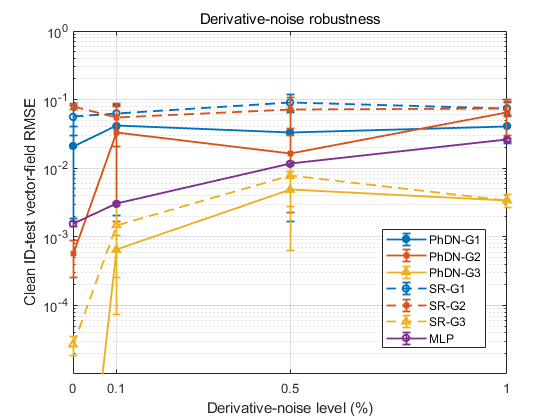


noiseRows = systemIdentificationRows;
% Restrict manuscript-facing outputs to the CURRENT requested noise grid,
% rounds, and comparison methods. Historical checkpoints/results remain on
% disk and in allResults, but old 5%/10% rows cannot leak into the new
% 0--1% robustness CSVs/figure/compact cache.
if ~isempty(noiseRows)
    keepNoise = false(1,numel(noiseRows));
    for iNoiseKeep = 1:numel(NoiseLevels)
        keepNoise = keepNoise | ...
            abs([noiseRows.noiseLevel]-NoiseLevels(iNoiseKeep)) < 1e-14;
    end
    keepRound = [noiseRows.roundIndex] >= 1 & ...
                [noiseRows.roundIndex] <= NumRounds;
    keepMethod = ismember(lower(string({noiseRows.method})), ...
        lower(string(RobustnessComparisonMethods)));
    noiseRows = noiseRows(keepNoise & keepRound & keepMethod);
end
% Stable deterministic ordering: round, noise level, then method order.
if ~isempty(noiseRows)
    methodRank = zeros(1,numel(noiseRows));
    for iRowSort = 1:numel(noiseRows)
        rankCandidate = find(strcmpi(RobustnessComparisonMethods,noiseRows(iRowSort).method),1);
        if isempty(rankCandidate); rankCandidate = numel(RobustnessComparisonMethods)+1; end
        methodRank(iRowSort) = rankCandidate;
    end
    [~,rowOrder] = sortrows([[noiseRows.roundIndex].', [noiseRows.noiseLevel].', methodRank.'],[1 2 3]);
    noiseRows = noiseRows(rowOrder);
end
detailedTable = single_generator_dynamic_noise_rows_to_table(noiseRows);
writetable(detailedTable,fullfile(OutputSummaryDir,'generator_noise_robustness_all_runs.csv'));

[figNoise,noiseFigureData,noiseSummaryTable] = ...
    plot_single_generator_dynamic_noise_robustness(noiseRows,'Visible',true);
summaryCsvPath = fullfile(OutputSummaryDir,'generator_noise_robustness_mean_std.csv');
writetable(noiseSummaryTable,summaryCsvPath);
figureDataPath = fullfile(OutputSummaryDir,'generator_noise_robustness_figure_data.mat');
save(figureDataPath,'noiseFigureData','noiseSummaryTable','-v7.3');
figPath = fullfile(OutputSummaryDir,'generator_noise_robustness.fig');
pdfPath = fullfile(OutputSummaryDir,'generator_noise_robustness.pdf');
savefig(figNoise,figPath);
try
    exportgraphics(figNoise,pdfPath,'ContentType','vector');
catch
    set(figNoise,'PaperPositionMode','auto');
    print(figNoise,pdfPath,'-dpdf','-painters');
end


protocol = struct();
protocol.system = 'SingleGeneratorDynamic_SMIB_AVR';
protocol.prior = 'G1_G2_G3';
protocol.comparisonMethods = RobustnessComparisonMethods;
protocol.includeStage0SRAblationsInComparison = IncludeStage0SRAblationsInComparison;
protocol.incrementalMergeEnabled = true;
protocol.nTrain = TrainingSampleList;
protocol.noiseLevels = NoiseLevels;
protocol.numRounds = NumRounds;
protocol.noiseFormula = 'Y_tilde(:,j)=Y(:,j)+rho*std(Ytrain_clean(:,j))*epsilon(:,j)';
protocol.trainValidationNoisy = true;
protocol.idTestClean = true;
protocol.oodEnabled = false;
protocol.rolloutEnabled = false;
protocol.fixedStateSamplesAcrossRounds = true;
protocol.pairedNoiseRealizationAcrossRhoWithinRound = true;
protocol.baseNoiseSeed = BaseNoiseSeed;
protocol.stage0BypassMode = 'fixed_noise_agnostic_validation_mse';
protocol.stage0BypassThreshold = Stage0SingleLayerBypassThreshold;
protocol.stage0TotalPopulations = Stage0InnerPopulations;
protocol.primaryMetric = 'clean_id_test_vector_field_rmse';
protocol.stateSeeds = [BaseTrainPoolSeed,BaseValidationPoolSeed,BaseTestPoolSeed];
protocol.completeCaseWallTime = completeCaseWallTime;
save(CompactRowsFile,'noiseRows','-v7');
save(ResultsFile,'allResults','noiseRows','noiseSummaryTable','protocol','-v7.3');

fprintf('Noise robustness outputs saved under:\n%s\n',OutputCaseRoot);

Noise robustness outputs saved under:
D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR_NoiseRobustness


fprintf('Aggregate MAT: %s\n',ResultsFile);

Aggregate MAT: D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR_NoiseRobustness\summary\single_generator_dynamic_noise_robustness_results.mat


fprintf('Detailed CSV : %s\n',fullfile(OutputSummaryDir,'generator_noise_robustness_all_runs.csv'));

Detailed CSV : D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR_NoiseRobustness\summary\generator_noise_robustness_all_runs.csv


fprintf('Mean/std CSV : %s\n',summaryCsvPath);

Mean/std CSV : D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR_NoiseRobustness\summary\generator_noise_robustness_mean_std.csv


fprintf('Paper PDF    : %s\n',pdfPath);

Paper PDF    : D:\PSU\research\operator learning\operator regression\PhD-NN start at 20260509\PHDNN_LSQ_Framework_v75_PySR2_shared_initial_guesses_full\outputs\SingleGeneratorDynamic_SMIB_AVR_NoiseRobustness\summary\generator_noise_robustness.pdf
